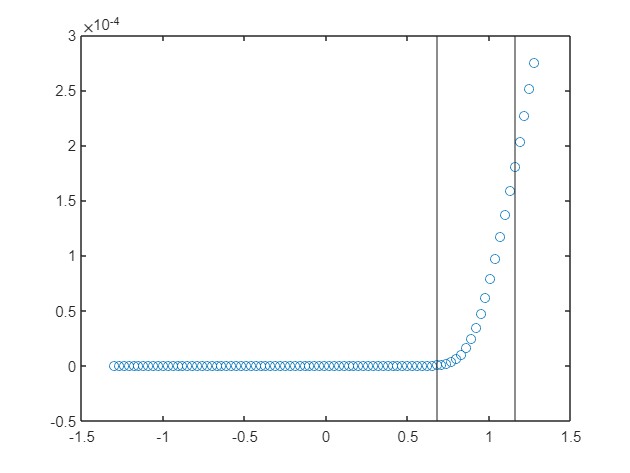

clearvars; close all;
addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));

TEMPERATURE = 298; % K
TEMPERATUREStd = 3; % Assuming uncertainty on the temperature of +- 3K
V_T = 0.02585*TEMPERATURE/300; % Thermal voltage in V
V_TStd = V_T*TEMPERATUREStd/TEMPERATURE;

% Import
LPath = 'D:\Profile\qse\Files\_EDMRoC pinSC\IV curve\SuSi\a-Si_pin_Solar_Cell_AM1p5G.txt';

ivdata = importdata(LPath, '\t', 21);
V = ivdata.data(:,1);
I = (ivdata.data(:,2) + ivdata.data(:,3))/2; % mA/cm^2
I = I/1000/100; % A
nI = numel(I);

figure()
plot(V, I, 'o')
xline(V(67)) % IDX_START_IN
xline(V(83)) % IDX_START_FIN

# Spike in the measurement at negative voltage

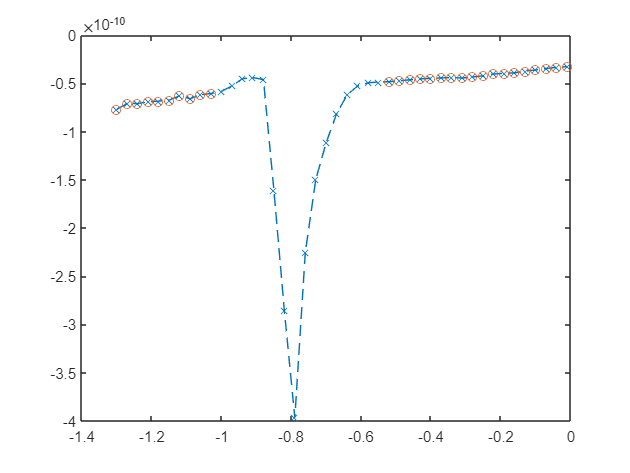

Vrange = [-1.4 -1 -0.55 0.];
idxLow = (V > Vrange(1) & V < Vrange(2)) | (V > Vrange(3) & V < Vrange(4));

VLow = V(idxLow); ILow = I(idxLow);
figure()
plot(V(V<0), I(V<0), 'x--')
hold on
plot(VLow, ILow, 'o')

# Fit in the forward bias region

## Caluclate the x y pairs

nStart = 17;
IDX_START_IN = 67;
IDX_START_FIN = IDX_START_IN + nStart - 1; % Should always be smaller than nI - 1
linModel = @(x, p) p(1)*x + p(2);

Varying the initial value of i0 between IDX_START_IN and IDS_START_FIN. For each idxStart perform the complete algorithm and in the end compare the results.

for idxStart = IDX_START_IN:IDX_START_FIN
    ny = (nI - idxStart + 1)*(nI - idxStart)/2;
    [x, y] = deal(zeros(ny, 1)); 
    iy = 1;
    for i0 = idxStart:nI - 1
        I0 = I(i0);
        V0 = V(i0);
        for ii = i0 + 1:nI
            y(iy) = log(I(ii)/I0)/(I(ii)-I0);
            x(iy) = (V(ii)-V0)/(I(ii)-I0);
            iy = iy + 1;
        end
    end

## Ectract $\alpha \;$and $R_s$


$$y=\alpha \;\left(-R_S +x\right)=\alpha \;x-R_{S\;} \alpha \;$$
 

    p0 = [19, -2e4]; vary = [5, 2e4];
    ii = idxStart - IDX_START_IN + 1; % Index for the result arrays
%     figure()
%     plot(x, y, 'o')
%     hold on
%     plot(x, linModel(x, p0))
    FitOpt.x = x;   % Necessary because (x y) pairs are not increasingly ordered
    X = [x ones(size(x))];
    param = X \y;
    disp(fprintf("==============\n==============\n==============\nidxStrart = %i\n==============\n==============\n==============", idxStart))
    Fit1{ii} = esfit(y, @(p) linModel(x, p), p0, vary, FitOpt);

    xDummy = linspace(min(x), max(x), 1000);
    figure()
    plot(x, y, 'o')
    hold on
    plot(xDummy, Fit1{ii}.scale*Fit1{ii}.pfit(1)*xDummy + Fit1{ii}.scale*Fit1{ii}.pfit(2))
    xlim(setAxLim(x, 0.1))
    ylim(setAxLim(y, 0.1))

## Extract Is


$$\ln \left(I\right)=\ln \left(I_{\textrm{s1}} \right)+\alpha_1 \left(V-I*R_s \right)$$


    Rs_ = -Fit1{ii}.pfit(2)/Fit1{ii}.pfit(1);
    Vc = V(idxStart:end) - I(idxStart:end)*Rs_; % Corrected voltage values
    lnI = log(I(idxStart:end));

    p0 = [18.8, -30]; vary = [18, 100];
    Fit2{ii} = esfit(lnI,@(p) linModel(Vc, p), p0, vary);
    
    xDummy = linspace(min(Vc), max(Vc), 1000);
    figure()
    plot(Vc, lnI, 'o')
    hold on
    plot(xDummy, Fit2{ii}.scale*Fit2{ii}.pfit(1)*xDummy + Fit2{ii}.scale*Fit2{ii}.pfit(2))
    xlim(setAxLim(Vc, 0.1))
    ylim(setAxLim(lnI, 0.1))


## Extract $R_{\textrm{sh}}$


$$I=\frac{V_C }{R_{\textrm{sh}} }$$


idxStrart = 67
==============   104



-- esfit ------------------------------------------------
Data size:                [210, 1]
Model function name:      @(p)linModel(x,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 1.90046e+03   edge 1.00000e-01   initial simplex
iteration   2: value 1.90046e+03   edge 4.00000e+03   reflection
iteration   3: value 1.77049e+03   edge 3.00000e+03   contraction inside
iteration   4: value 1.39265e+03   edge 2.25000e+03   contraction inside
iteration   5: value 1.39265e+03   edge 1.25000e+03   reflection
iteration   6: value 1.39265e+03   edge 1.00000e+03   contraction inside
iteration   7: value 1.38913e+03   edge 9.37500e+02   contraction inside
iteration   8: value 1.38913e+03   edge 5.15625e+02   contraction outside
iteration   9: value 1.38493e+03   edge 

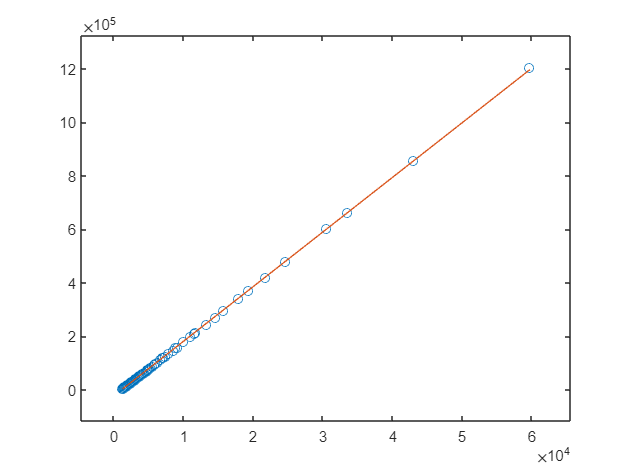

-- esfit ------------------------------------------------
Data size:                [21, 1]
Model function name:      @(p)linModel(Vc,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 1.54908e-01   edge 1.00000e-01   initial simplex
iteration   2: value 1.54908e-01   edge 1.00000e+01   contraction outside
iteration   3: value 1.54908e-01   edge 5.00000e+00   contraction inside
iteration   4: value 1.16638e-01   edge 2.50000e+00   contraction outside
iteration   5: value 1.16638e-01   edge 2.50000e+00   contraction inside
iteration   6: value 1.09047e-01   edge 1.65938e+00   contraction inside
iteration   7: value 9.40112e-02   edge 1.64062e+00   contraction inside
iteration   8: value 7.41182e-02   edge 8.39844e-01   contraction inside
iteration   9: value 6.

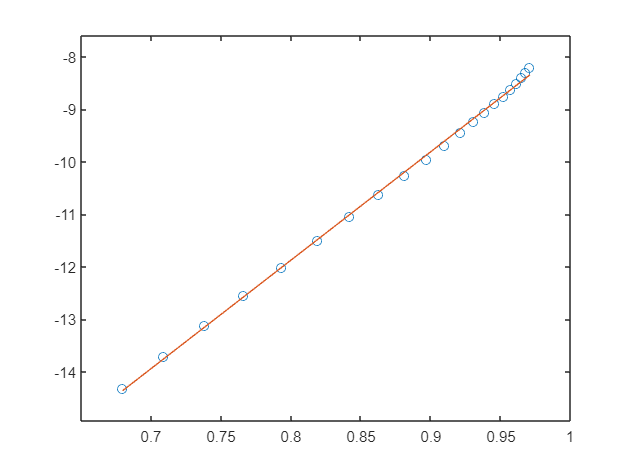

-- esfit ------------------------------------------------
Data size:                [28, 1]
Model function name:      @(p)linModel(Vc_,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 2.03778e-11   edge 1.00000e-01   initial simplex
iteration   2: value 2.03251e-11   edge 3.00000e+07   expansion
iteration   3: value 2.03251e-11   edge 2.00000e+07   reflection
iteration   4: value 2.03251e-11   edge 3.00000e+07   reflection
iteration   5: value 2.02651e-11   edge 2.50000e+07   expansion
iteration   6: value 2.02651e-11   edge 3.00000e+07   reflection
iteration   7: value 2.02651e-11   edge 3.00000e+07   reflection
iteration   8: value 1.99858e-11   edge 3.00000e+07   reflection
iteration   9: value 1.96007e-11   edge 3.00000e+07   reflection
iteration  10: va

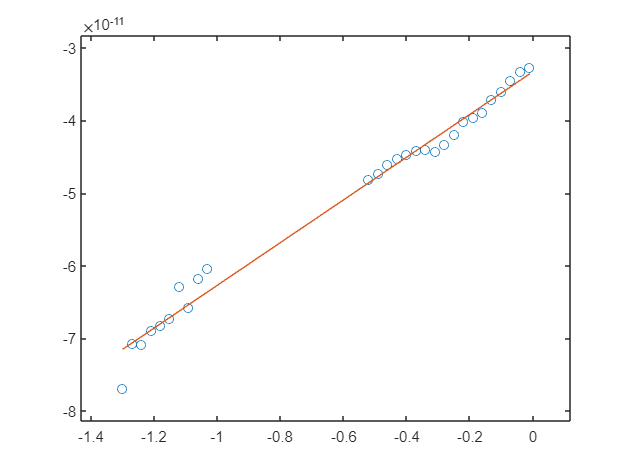

idxStrart = 68
==============   104



-- esfit ------------------------------------------------
Data size:                [190, 1]
Model function name:      @(p)linModel(x,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 1.35442e+03   edge 1.00000e-01   initial simplex
iteration   2: value 1.35442e+03   edge 4.00000e+03   reflection
iteration   3: value 1.23437e+03   edge 3.00000e+03   contraction inside
iteration   4: value 1.10604e+03   edge 2.25000e+03   contraction inside
iteration   5: value 1.10604e+03   edge 1.25000e+03   reflection
iteration   6: value 1.00301e+03   edge 1.37500e+03   contraction inside
iteration   7: value 1.00301e+03   edge 1.00000e+03   reflection
iteration   8: value 1.00301e+03   edge 1.00000e+03   contraction inside
iteration   9: value 1.00301e+03   edge 5.15625e+

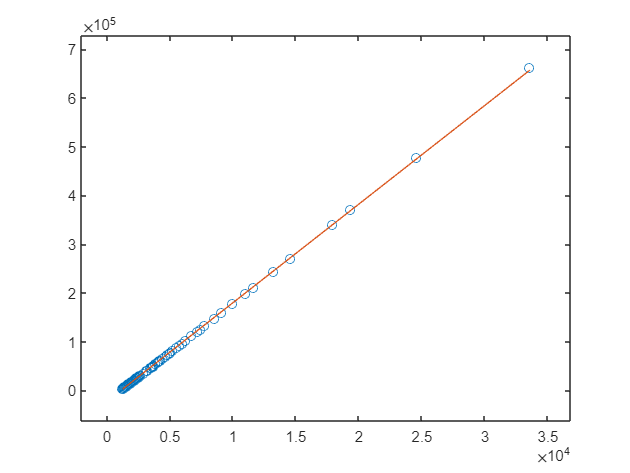

-- esfit ------------------------------------------------
Data size:                [20, 1]
Model function name:      @(p)linModel(Vc,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 1.68327e-01   edge 1.00000e-01   initial simplex
iteration   2: value 1.68327e-01   edge 1.00000e+01   contraction outside
iteration   3: value 1.68327e-01   edge 5.00000e+00   contraction inside
iteration   4: value 1.68327e-01   edge 3.60000e+00   contraction inside
iteration   5: value 1.68327e-01   edge 2.50000e+00   reflection
iteration   6: value 1.68327e-01   edge 2.50000e+00   contraction inside
iteration   7: value 9.83868e-02   edge 1.71875e+00   contraction inside
iteration   8: value 5.59163e-02   edge 1.36719e+00   contraction inside
iteration   9: value 5.59163e-02

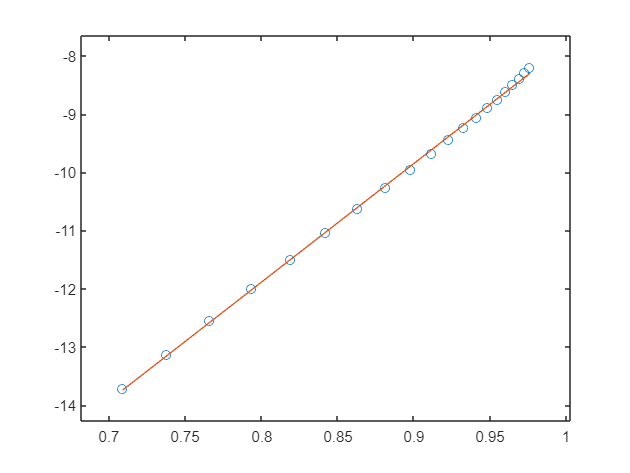

-- esfit ------------------------------------------------
Data size:                [28, 1]
Model function name:      @(p)linModel(Vc_,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 2.04403e-11   edge 1.00000e-01   initial simplex
iteration   2: value 2.03875e-11   edge 3.00000e+07   expansion
iteration   3: value 2.03875e-11   edge 2.00000e+07   reflection
iteration   4: value 2.03875e-11   edge 3.00000e+07   reflection
iteration   5: value 2.03274e-11   edge 2.50000e+07   expansion
iteration   6: value 2.03274e-11   edge 3.00000e+07   reflection
iteration   7: value 2.03274e-11   edge 3.00000e+07   reflection
iteration   8: value 2.00475e-11   edge 3.00000e+07   reflection
iteration   9: value 1.96617e-11   edge 3.00000e+07   reflection
iteration  10: va

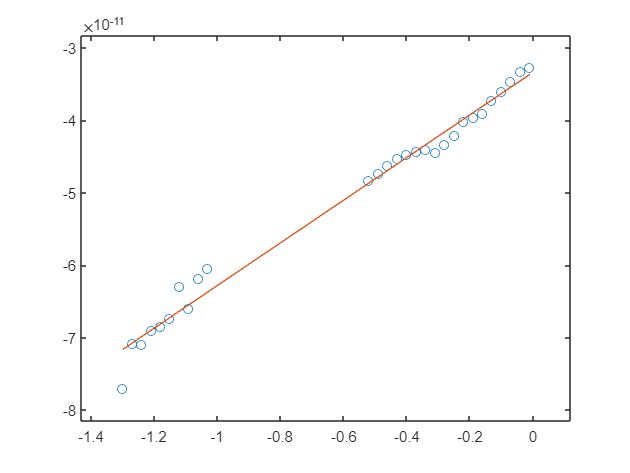

idxStrart = 69
==============   104



-- esfit ------------------------------------------------
Data size:                [171, 1]
Model function name:      @(p)linModel(x,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 9.44296e+02   edge 1.00000e-01   initial simplex
iteration   2: value 8.59680e+02   edge 2.00000e+03   contraction outside
iteration   3: value 8.59680e+02   edge 2.00000e+03   contraction inside
iteration   4: value 7.96466e+02   edge 1.25000e+03   contraction outside
iteration   5: value 7.44113e+02   edge 1.18750e+03   contraction inside
iteration   6: value 7.44113e+02   edge 7.50000e+02   reflection
iteration   7: value 7.39156e+02   edge 7.81250e+02   contraction inside
iteration   8: value 7.39156e+02   edge 3.67188e+02   contraction outside
iteration   9: value 7.36784e+

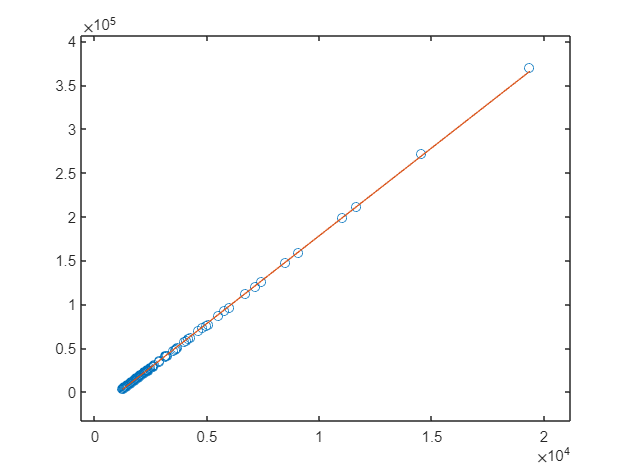

-- esfit ------------------------------------------------
Data size:                [19, 1]
Model function name:      @(p)linModel(Vc,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 1.79425e-01   edge 1.00000e-01   initial simplex
iteration   2: value 1.79425e-01   edge 1.00000e+01   contraction outside
iteration   3: value 1.79425e-01   edge 5.00000e+00   contraction inside
iteration   4: value 1.79425e-01   edge 3.60000e+00   contraction inside
iteration   5: value 1.79425e-01   edge 2.50000e+00   reflection
iteration   6: value 1.34561e-01   edge 2.30625e+00   contraction inside
iteration   7: value 9.29866e-02   edge 1.71875e+00   contraction outside
iteration   8: value 3.86266e-02   edge 1.36719e+00   contraction inside
iteration   9: value 3.86266e-0

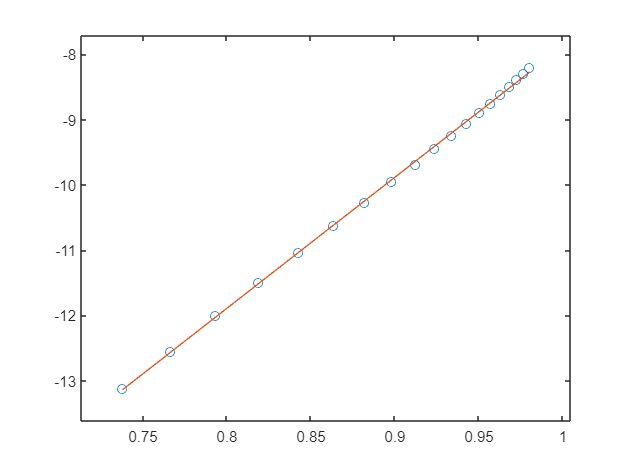

-- esfit ------------------------------------------------
Data size:                [28, 1]
Model function name:      @(p)linModel(Vc_,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 2.04355e-11   edge 1.00000e-01   initial simplex
iteration   2: value 2.03827e-11   edge 3.00000e+07   expansion
iteration   3: value 2.03827e-11   edge 2.00000e+07   reflection
iteration   4: value 2.03827e-11   edge 3.00000e+07   reflection
iteration   5: value 2.03225e-11   edge 2.50000e+07   expansion
iteration   6: value 2.03225e-11   edge 3.00000e+07   reflection
iteration   7: value 2.03225e-11   edge 3.00000e+07   reflection
iteration   8: value 2.00427e-11   edge 3.00000e+07   reflection
iteration   9: value 1.96570e-11   edge 3.00000e+07   reflection
iteration  10: va

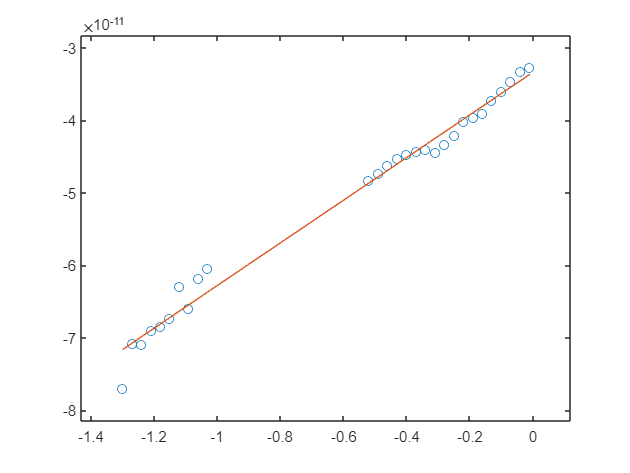

idxStrart = 70
==============   104



-- esfit ------------------------------------------------
Data size:                [153, 1]
Model function name:      @(p)linModel(x,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 5.87960e+02   edge 1.00000e-01   initial simplex
iteration   2: value 5.87960e+02   edge 2.00000e+03   contraction outside
iteration   3: value 5.87960e+02   edge 2.00000e+03   contraction inside
iteration   4: value 5.18709e+02   edge 1.12500e+03   contraction inside
iteration   5: value 5.16351e+02   edge 5.93750e+02   contraction outside
iteration   6: value 5.10335e+02   edge 6.95312e+02   contraction inside
iteration   7: value 5.10335e+02   edge 5.31250e+02   reflection
iteration   8: value 5.02482e+02   edge 4.80469e+02   contraction inside
iteration   9: value 5.02482e+0

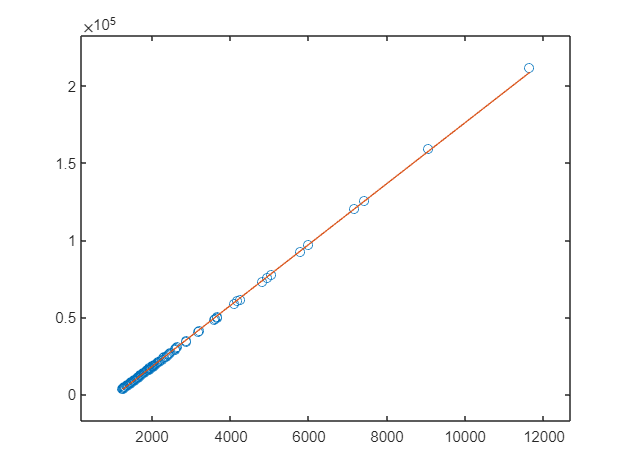

-- esfit ------------------------------------------------
Data size:                [18, 1]
Model function name:      @(p)linModel(Vc,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 1.89931e-01   edge 1.00000e-01   initial simplex
iteration   2: value 1.89931e-01   edge 1.00000e+01   contraction outside
iteration   3: value 1.89931e-01   edge 5.00000e+00   contraction inside
iteration   4: value 1.89931e-01   edge 3.60000e+00   contraction inside
iteration   5: value 1.89931e-01   edge 2.50000e+00   reflection
iteration   6: value 9.63897e-02   edge 2.30625e+00   contraction inside
iteration   7: value 9.63897e-02   edge 2.50000e+00   reflection
iteration   8: value 3.10742e-02   edge 1.65938e+00   contraction inside
iteration   9: value 3.10742e-02   edge 

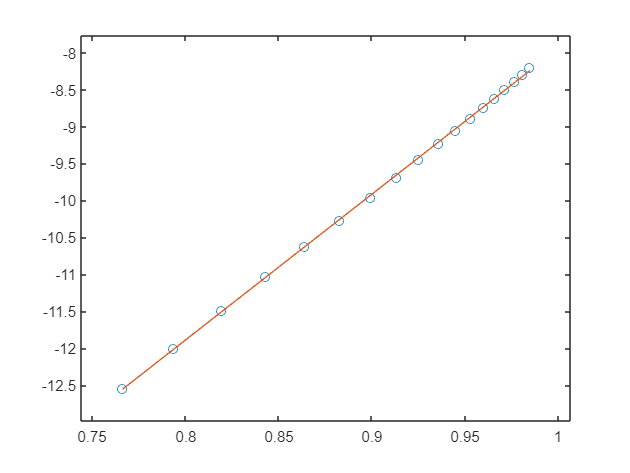

-- esfit ------------------------------------------------
Data size:                [28, 1]
Model function name:      @(p)linModel(Vc_,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 2.04424e-11   edge 1.00000e-01   initial simplex
iteration   2: value 2.03896e-11   edge 3.00000e+07   expansion
iteration   3: value 2.03896e-11   edge 2.00000e+07   reflection
iteration   4: value 2.03896e-11   edge 3.00000e+07   reflection
iteration   5: value 2.03294e-11   edge 2.50000e+07   expansion
iteration   6: value 2.03294e-11   edge 3.00000e+07   reflection
iteration   7: value 2.03294e-11   edge 3.00000e+07   reflection
iteration   8: value 2.00495e-11   edge 3.00000e+07   reflection
iteration   9: value 1.96637e-11   edge 3.00000e+07   reflection
iteration  10: va

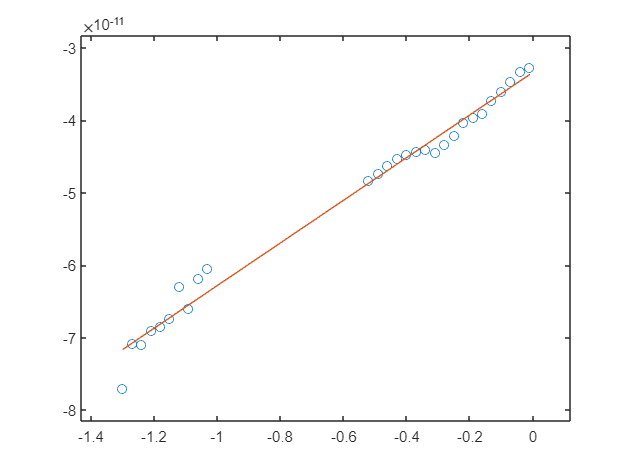

idxStrart = 71
==============   104



-- esfit ------------------------------------------------
Data size:                [136, 1]
Model function name:      @(p)linModel(x,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 3.25808e+02   edge 1.00000e-01   initial simplex
iteration   2: value 3.25808e+02   edge 2.00000e+03   contraction outside
iteration   3: value 3.25808e+02   edge 2.00000e+03   contraction inside
iteration   4: value 3.25808e+02   edge 1.12500e+03   contraction inside
iteration   5: value 3.21987e+02   edge 6.87500e+02   contraction inside
iteration   6: value 3.21987e+02   edge 6.87500e+02   contraction inside
iteration   7: value 3.18813e+02   edge 3.82812e+02   contraction outside
iteration   8: value 3.14408e+02   edge 4.39453e+02   contraction inside
iteration   9: value 3.

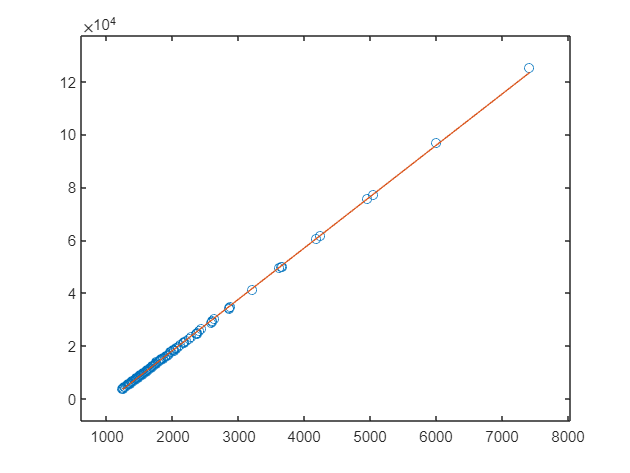

-- esfit ------------------------------------------------
Data size:                [17, 1]
Model function name:      @(p)linModel(Vc,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 1.96562e-01   edge 1.00000e-01   initial simplex
iteration   2: value 1.96562e-01   edge 1.00000e+01   contraction outside
iteration   3: value 1.96562e-01   edge 5.00000e+00   contraction inside
iteration   4: value 1.96562e-01   edge 3.60000e+00   contraction inside
iteration   5: value 1.96562e-01   edge 2.50000e+00   reflection
iteration   6: value 6.35864e-02   edge 2.30625e+00   contraction inside
iteration   7: value 6.35864e-02   edge 2.50000e+00   reflection
iteration   8: value 4.63402e-02   edge 1.65938e+00   contraction inside
iteration   9: value 3.58011e-02   edge 

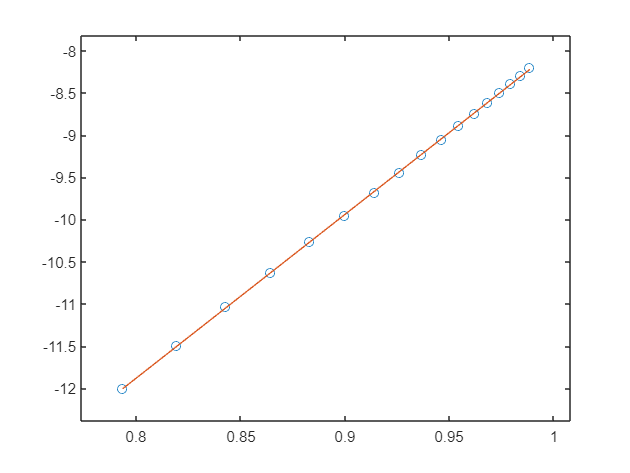

-- esfit ------------------------------------------------
Data size:                [28, 1]
Model function name:      @(p)linModel(Vc_,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 2.04398e-11   edge 1.00000e-01   initial simplex
iteration   2: value 2.03871e-11   edge 3.00000e+07   expansion
iteration   3: value 2.03871e-11   edge 2.00000e+07   reflection
iteration   4: value 2.03871e-11   edge 3.00000e+07   reflection
iteration   5: value 2.03269e-11   edge 2.50000e+07   expansion
iteration   6: value 2.03269e-11   edge 3.00000e+07   reflection
iteration   7: value 2.03269e-11   edge 3.00000e+07   reflection
iteration   8: value 2.00470e-11   edge 3.00000e+07   reflection
iteration   9: value 1.96612e-11   edge 3.00000e+07   reflection
iteration  10: va

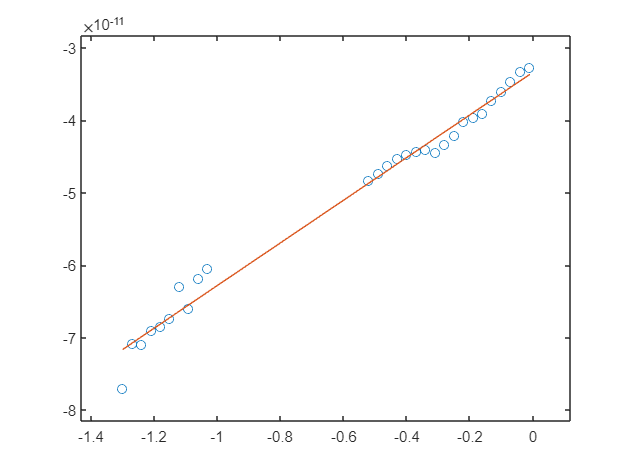

idxStrart = 72
==============   104



-- esfit ------------------------------------------------
Data size:                [120, 1]
Model function name:      @(p)linModel(x,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 2.01577e+02   edge 1.00000e-01   initial simplex
iteration   2: value 2.01577e+02   edge 2.00000e+03   contraction outside
iteration   3: value 2.01577e+02   edge 1.00000e+03   contraction inside
iteration   4: value 2.01577e+02   edge 1.00000e+03   contraction inside
iteration   5: value 2.01577e+02   edge 5.62500e+02   contraction inside
iteration   6: value 2.01577e+02   edge 5.62500e+02   contraction inside
iteration   7: value 1.98517e+02   edge 3.47656e+02   contraction inside
iteration   8: value 1.95227e+02   edge 2.19727e+02   contraction inside
iteration   9: value 1.9

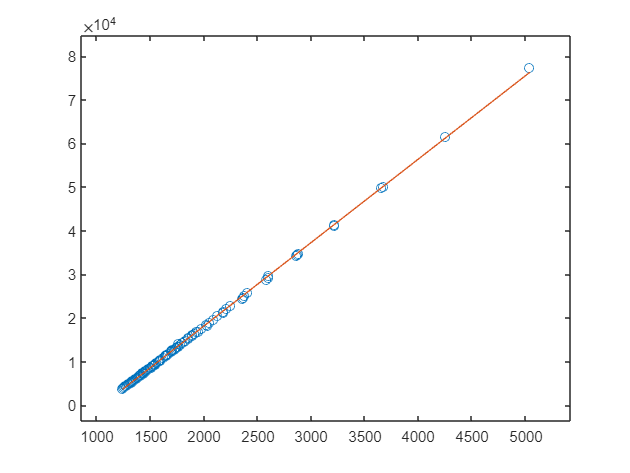

-- esfit ------------------------------------------------
Data size:                [16, 1]
Model function name:      @(p)linModel(Vc,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 1.96036e-01   edge 1.00000e-01   initial simplex
iteration   2: value 1.96036e-01   edge 1.00000e+01   contraction outside
iteration   3: value 1.96036e-01   edge 5.00000e+00   contraction inside
iteration   4: value 1.96036e-01   edge 3.60000e+00   contraction inside
iteration   5: value 7.88423e-02   edge 2.19375e+00   contraction outside
iteration   6: value 6.74159e-02   edge 1.71875e+00   contraction inside
iteration   7: value 6.74159e-02   edge 1.25156e+00   contraction outside
iteration   8: value 6.18101e-03   edge 7.81348e-01   contraction inside
iteration   9: value 6

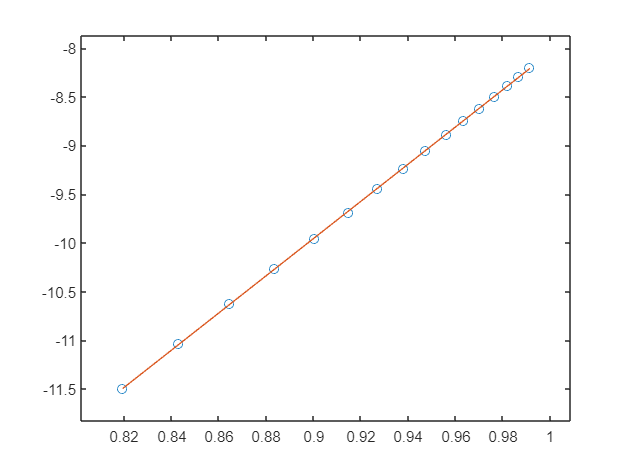

-- esfit ------------------------------------------------
Data size:                [28, 1]
Model function name:      @(p)linModel(Vc_,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 2.04226e-11   edge 1.00000e-01   initial simplex
iteration   2: value 2.03699e-11   edge 3.00000e+07   expansion
iteration   3: value 2.03699e-11   edge 2.00000e+07   reflection
iteration   4: value 2.03699e-11   edge 3.00000e+07   reflection
iteration   5: value 2.03097e-11   edge 2.50000e+07   expansion
iteration   6: value 2.03097e-11   edge 3.00000e+07   reflection
iteration   7: value 2.03097e-11   edge 3.00000e+07   reflection
iteration   8: value 2.00300e-11   edge 3.00000e+07   reflection
iteration   9: value 1.96444e-11   edge 3.00000e+07   reflection
iteration  10: va

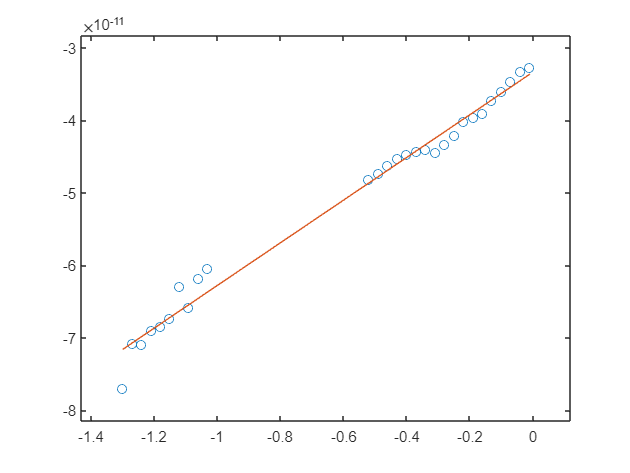

idxStrart = 73
==============   104



-- esfit ------------------------------------------------
Data size:                [105, 1]
Model function name:      @(p)linModel(x,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 1.79694e+02   edge 1.00000e-01   initial simplex
iteration   2: value 1.79694e+02   edge 2.00000e+03   contraction inside
iteration   3: value 1.79694e+02   edge 1.00000e+03   contraction outside
iteration   4: value 1.66102e+02   edge 7.50000e+02   contraction inside
iteration   5: value 1.66102e+02   edge 5.62500e+02   contraction outside
iteration   6: value 1.43681e+02   edge 3.43750e+02   contraction inside
iteration   7: value 1.25849e+02   edge 2.10938e+02   contraction inside
iteration   8: value 1.25849e+02   edge 3.43750e+02   reflection
iteration   9: value 1.25849e+0

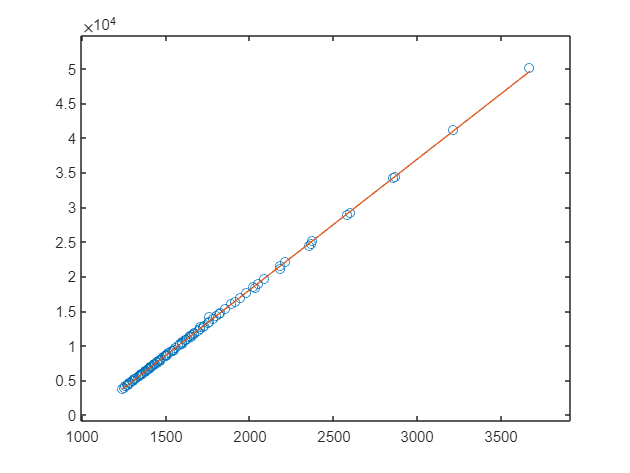

-- esfit ------------------------------------------------
Data size:                [15, 1]
Model function name:      @(p)linModel(Vc,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 1.89169e-01   edge 1.00000e-01   initial simplex
iteration   2: value 1.89169e-01   edge 1.00000e+01   contraction outside
iteration   3: value 1.89169e-01   edge 5.00000e+00   contraction inside
iteration   4: value 1.80695e-01   edge 2.50000e+00   contraction inside
iteration   5: value 8.37005e-02   edge 2.19375e+00   contraction outside
iteration   6: value 4.69356e-02   edge 1.40625e+00   contraction inside
iteration   7: value 4.69356e-02   edge 8.98438e-01   contraction inside
iteration   8: value 3.24233e-02   edge 7.69043e-01   contraction inside
iteration   9: value 1.

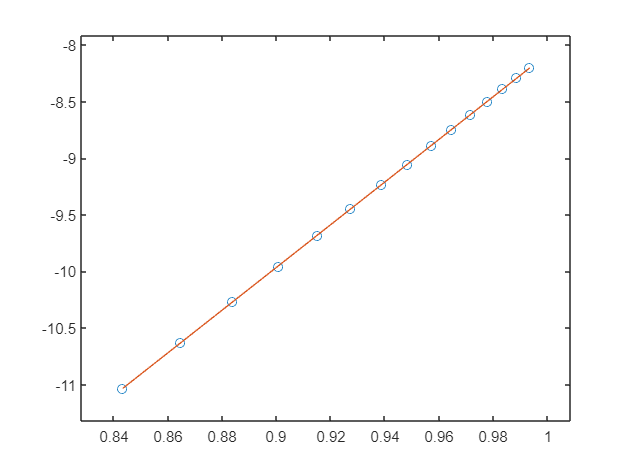

-- esfit ------------------------------------------------
Data size:                [28, 1]
Model function name:      @(p)linModel(Vc_,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 2.04283e-11   edge 1.00000e-01   initial simplex
iteration   2: value 2.03755e-11   edge 3.00000e+07   expansion
iteration   3: value 2.03755e-11   edge 2.00000e+07   reflection
iteration   4: value 2.03755e-11   edge 3.00000e+07   reflection
iteration   5: value 2.03153e-11   edge 2.50000e+07   expansion
iteration   6: value 2.03153e-11   edge 3.00000e+07   reflection
iteration   7: value 2.03153e-11   edge 3.00000e+07   reflection
iteration   8: value 2.00356e-11   edge 3.00000e+07   reflection
iteration   9: value 1.96499e-11   edge 3.00000e+07   reflection
iteration  10: va

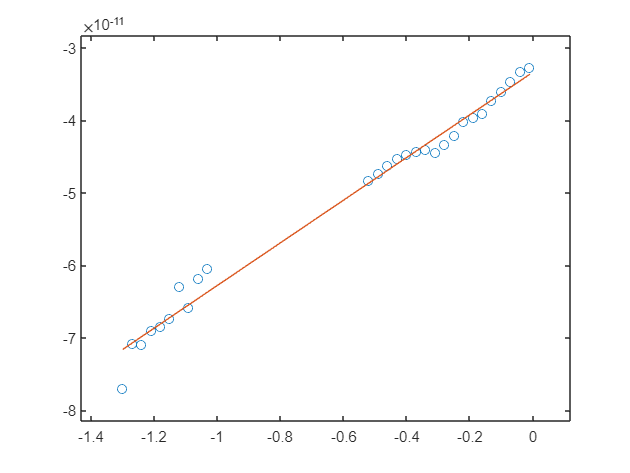

idxStrart = 74
==============   104



-- esfit ------------------------------------------------
Data size:                [91, 1]
Model function name:      @(p)linModel(x,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 1.86884e+02   edge 1.00000e-01   initial simplex
iteration   2: value 1.86884e+02   edge 2.00000e+03   contraction inside
iteration   3: value 1.86884e+02   edge 1.00000e+03   contraction outside
iteration   4: value 1.51492e+02   edge 5.00000e+02   contraction inside
iteration   5: value 1.45644e+02   edge 3.75000e+02   contraction inside
iteration   6: value 1.24112e+02   edge 3.43750e+02   contraction outside
iteration   7: value 1.03872e+02   edge 2.73438e+02   contraction inside
iteration   8: value 1.03872e+02   edge 3.43750e+02   reflection
iteration   9: value 1.03872e+02

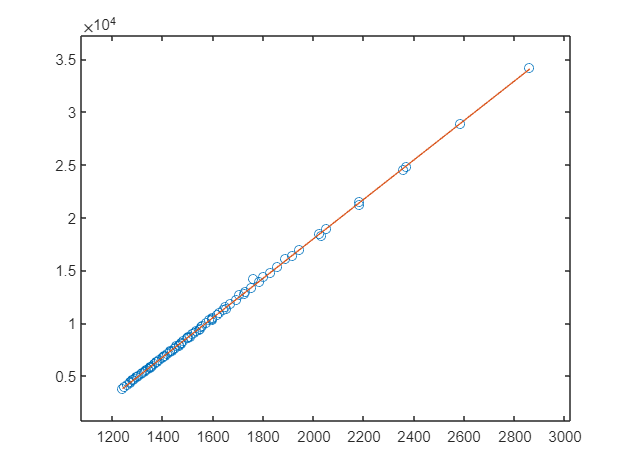

-- esfit ------------------------------------------------
Data size:                [14, 1]
Model function name:      @(p)linModel(Vc,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 1.75751e-01   edge 1.00000e-01   initial simplex
iteration   2: value 1.75751e-01   edge 1.00000e+01   contraction outside
iteration   3: value 1.75751e-01   edge 5.00000e+00   contraction inside
iteration   4: value 1.51609e-01   edge 2.50000e+00   contraction inside
iteration   5: value 1.05510e-01   edge 2.19375e+00   contraction inside
iteration   6: value 2.80647e-03   edge 1.71875e+00   contraction inside
iteration   7: value 2.80647e-03   edge 1.87500e+00   reflection
iteration   8: value 2.80647e-03   edge 1.87500e+00   contraction inside
iteration   9: value 2.80647e-03

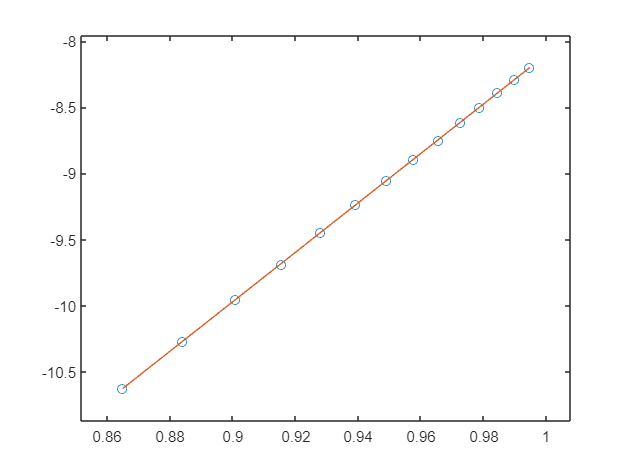

-- esfit ------------------------------------------------
Data size:                [28, 1]
Model function name:      @(p)linModel(Vc_,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 2.03118e-11   edge 1.00000e-01   initial simplex
iteration   2: value 2.02592e-11   edge 3.00000e+07   expansion
iteration   3: value 2.02592e-11   edge 2.00000e+07   reflection
iteration   4: value 2.02592e-11   edge 3.00000e+07   reflection
iteration   5: value 2.01993e-11   edge 2.50000e+07   expansion
iteration   6: value 2.01993e-11   edge 3.00000e+07   reflection
iteration   7: value 2.01993e-11   edge 3.00000e+07   reflection
iteration   8: value 1.99206e-11   edge 3.00000e+07   reflection
iteration   9: value 1.95364e-11   edge 3.00000e+07   reflection
iteration  10: va

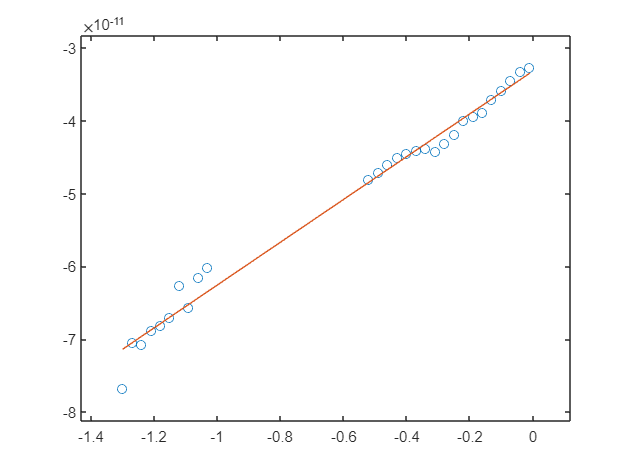

idxStrart = 75
==============   104



-- esfit ------------------------------------------------
Data size:                [78, 1]
Model function name:      @(p)linModel(x,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 1.79436e+02   edge 1.00000e-01   initial simplex
iteration   2: value 1.79436e+02   edge 2.00000e+03   contraction inside
iteration   3: value 1.79436e+02   edge 1.00000e+03   contraction inside
iteration   4: value 1.49989e+02   edge 5.00000e+02   contraction outside
iteration   5: value 1.34443e+02   edge 3.75000e+02   contraction inside
iteration   6: value 1.19400e+02   edge 3.43750e+02   contraction outside
iteration   7: value 1.09281e+02   edge 2.73438e+02   contraction inside
iteration   8: value 1.09281e+02   edge 3.43750e+02   reflection
iteration   9: value 1.08386e+02

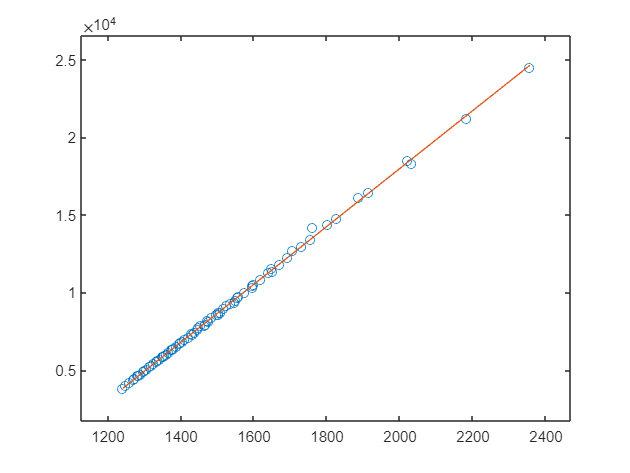

-- esfit ------------------------------------------------
Data size:                [13, 1]
Model function name:      @(p)linModel(Vc,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 1.55815e-01   edge 1.00000e-01   initial simplex
iteration   2: value 1.55815e-01   edge 1.00000e+01   contraction outside
iteration   3: value 1.55815e-01   edge 5.00000e+00   contraction inside
iteration   4: value 1.30393e-01   edge 2.50000e+00   contraction inside
iteration   5: value 9.03161e-02   edge 2.19375e+00   contraction inside
iteration   6: value 2.78906e-03   edge 1.71875e+00   contraction inside
iteration   7: value 2.78906e-03   edge 1.87500e+00   reflection
iteration   8: value 2.78906e-03   edge 1.87500e+00   contraction inside
iteration   9: value 2.78906e-03

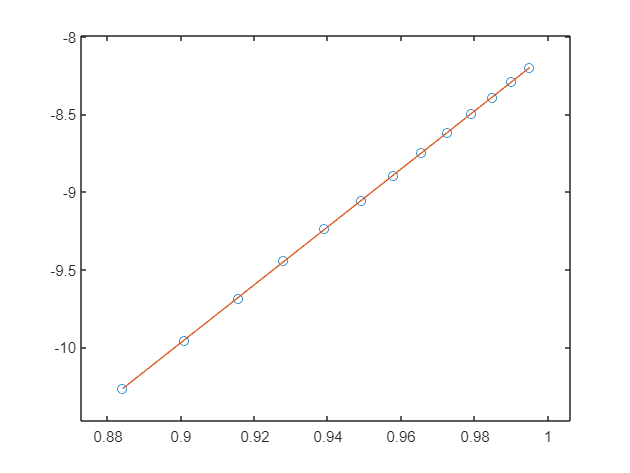

-- esfit ------------------------------------------------
Data size:                [28, 1]
Model function name:      @(p)linModel(Vc_,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 2.03220e-11   edge 1.00000e-01   initial simplex
iteration   2: value 2.02694e-11   edge 3.00000e+07   expansion
iteration   3: value 2.02694e-11   edge 2.00000e+07   reflection
iteration   4: value 2.02694e-11   edge 3.00000e+07   reflection
iteration   5: value 2.02094e-11   edge 2.50000e+07   expansion
iteration   6: value 2.02094e-11   edge 3.00000e+07   reflection
iteration   7: value 2.02094e-11   edge 3.00000e+07   reflection
iteration   8: value 1.99306e-11   edge 3.00000e+07   reflection
iteration   9: value 1.95463e-11   edge 3.00000e+07   reflection
iteration  10: va

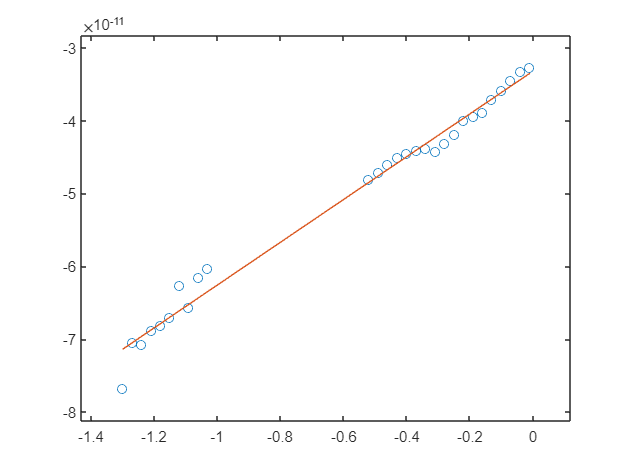

idxStrart = 76
==============   104



-- esfit ------------------------------------------------
Data size:                [66, 1]
Model function name:      @(p)linModel(x,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 1.55823e+02   edge 1.00000e-01   initial simplex
iteration   2: value 1.55823e+02   edge 2.00000e+03   contraction inside
iteration   3: value 1.55823e+02   edge 1.00000e+03   contraction inside
iteration   4: value 1.34261e+02   edge 5.00000e+02   contraction outside
iteration   5: value 1.34261e+02   edge 5.00000e+02   contraction inside
iteration   6: value 1.24998e+02   edge 3.43750e+02   contraction outside
iteration   7: value 1.17355e+02   edge 1.95312e+02   contraction inside
iteration   8: value 1.11700e+02   edge 1.38672e+02   contraction inside
iteration   9: value 1.1

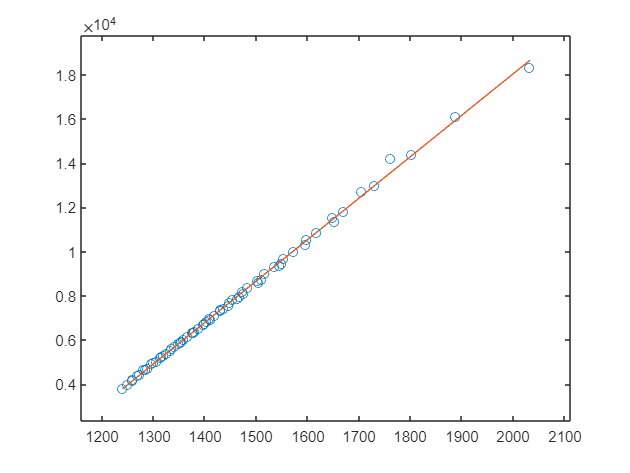

-- esfit ------------------------------------------------
Data size:                [12, 1]
Model function name:      @(p)linModel(Vc,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 1.31700e-01   edge 1.00000e-01   initial simplex
iteration   2: value 1.31700e-01   edge 1.00000e+01   contraction outside
iteration   3: value 1.31700e-01   edge 5.00000e+00   contraction inside
iteration   4: value 1.15252e-01   edge 2.50000e+00   contraction inside
iteration   5: value 8.08418e-02   edge 2.19375e+00   contraction inside
iteration   6: value 3.69769e-03   edge 1.71875e+00   contraction inside
iteration   7: value 3.69769e-03   edge 1.87500e+00   reflection
iteration   8: value 3.69769e-03   edge 1.87500e+00   contraction inside
iteration   9: value 3.69769e-03

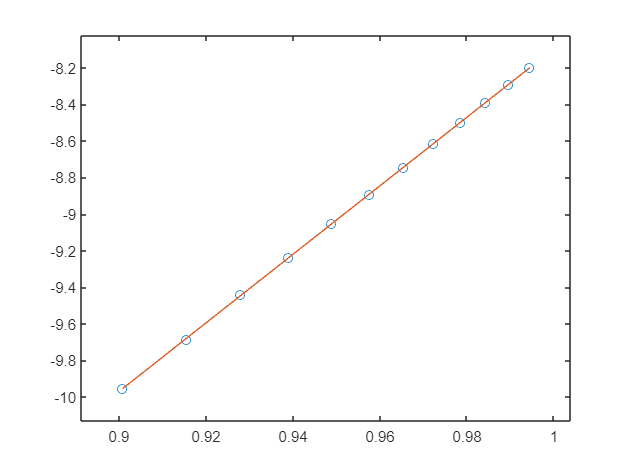

-- esfit ------------------------------------------------
Data size:                [28, 1]
Model function name:      @(p)linModel(Vc_,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 2.03042e-11   edge 1.00000e-01   initial simplex
iteration   2: value 2.02516e-11   edge 3.00000e+07   expansion
iteration   3: value 2.02516e-11   edge 2.00000e+07   reflection
iteration   4: value 2.02516e-11   edge 3.00000e+07   reflection
iteration   5: value 2.01917e-11   edge 2.50000e+07   expansion
iteration   6: value 2.01917e-11   edge 3.00000e+07   reflection
iteration   7: value 2.01917e-11   edge 3.00000e+07   reflection
iteration   8: value 1.99131e-11   edge 3.00000e+07   reflection
iteration   9: value 1.95290e-11   edge 3.00000e+07   reflection
iteration  10: va

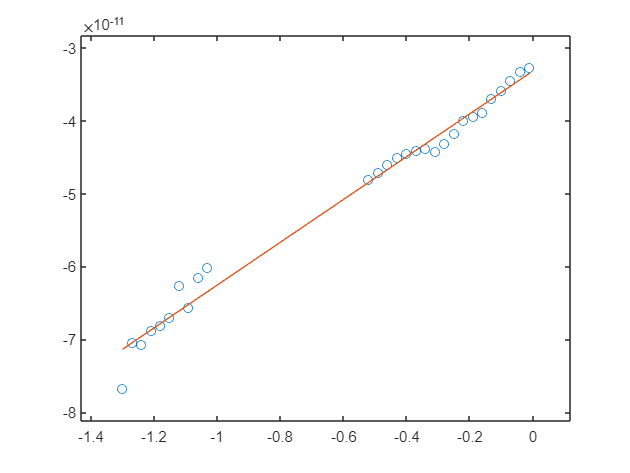

idxStrart = 77
==============   104



-- esfit ------------------------------------------------
Data size:                [55, 1]
Model function name:      @(p)linModel(x,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 1.35745e+02   edge 1.00000e-01   initial simplex
iteration   2: value 1.35745e+02   edge 2.00000e+03   contraction inside
iteration   3: value 1.35745e+02   edge 1.00000e+03   contraction inside
iteration   4: value 1.35745e+02   edge 1.00000e+03   reflection
iteration   5: value 1.21075e+02   edge 7.50000e+02   contraction inside
iteration   6: value 1.21075e+02   edge 5.62500e+02   contraction outside
iteration   7: value 1.09636e+02   edge 2.96875e+02   contraction inside
iteration   8: value 1.09636e+02   edge 5.62500e+02   reflection
iteration   9: value 1.09636e+02   edge 5

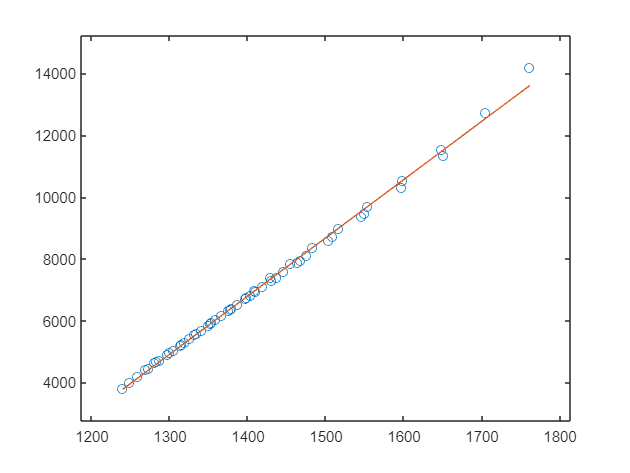

-- esfit ------------------------------------------------
Data size:                [11, 1]
Model function name:      @(p)linModel(Vc,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 1.10147e-01   edge 1.00000e-01   initial simplex
iteration   2: value 1.10147e-01   edge 1.00000e+01   contraction outside
iteration   3: value 1.10147e-01   edge 5.00000e+00   contraction inside
iteration   4: value 1.01674e-01   edge 2.50000e+00   contraction inside
iteration   5: value 7.22948e-02   edge 2.19375e+00   contraction inside
iteration   6: value 5.99540e-03   edge 1.71875e+00   contraction inside
iteration   7: value 5.99540e-03   edge 1.87500e+00   reflection
iteration   8: value 5.99540e-03   edge 1.87500e+00   contraction inside
iteration   9: value 5.99540e-03

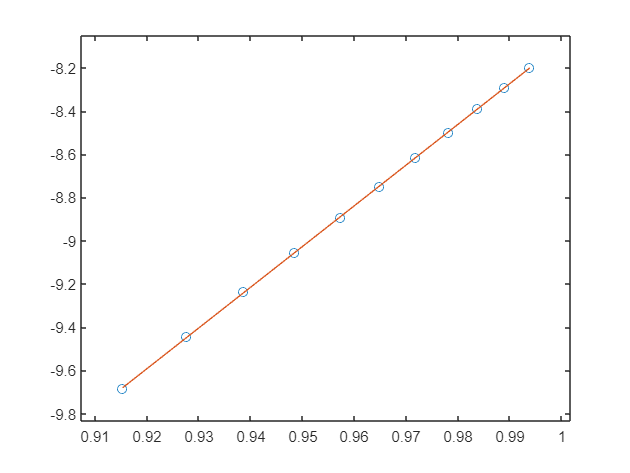

-- esfit ------------------------------------------------
Data size:                [28, 1]
Model function name:      @(p)linModel(Vc_,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 2.04002e-11   edge 1.00000e-01   initial simplex
iteration   2: value 2.03474e-11   edge 3.00000e+07   expansion
iteration   3: value 2.03474e-11   edge 2.00000e+07   reflection
iteration   4: value 2.03474e-11   edge 3.00000e+07   reflection
iteration   5: value 2.02873e-11   edge 2.50000e+07   expansion
iteration   6: value 2.02873e-11   edge 3.00000e+07   reflection
iteration   7: value 2.02873e-11   edge 3.00000e+07   reflection
iteration   8: value 2.00078e-11   edge 3.00000e+07   reflection
iteration   9: value 1.96225e-11   edge 3.00000e+07   reflection
iteration  10: va

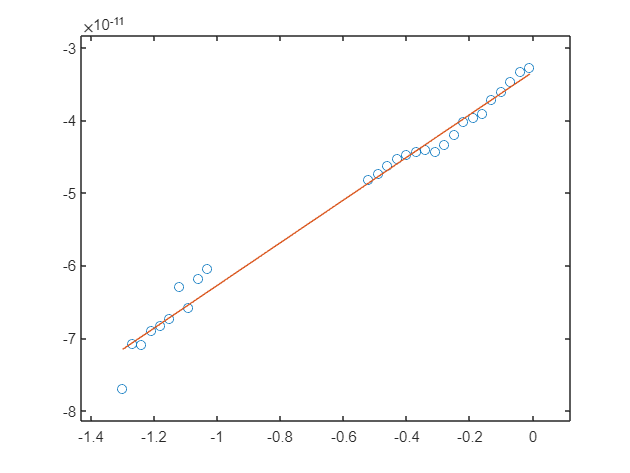

idxStrart = 78
==============   104



-- esfit ------------------------------------------------
Data size:                [45, 1]
Model function name:      @(p)linModel(x,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 1.17342e+02   edge 1.00000e-01   initial simplex
iteration   2: value 1.17342e+02   edge 2.00000e+03   contraction inside
iteration   3: value 1.17342e+02   edge 1.00000e+03   contraction inside
iteration   4: value 1.04162e+02   edge 5.00000e+02   contraction inside
iteration   5: value 1.96811e+01   edge 3.75000e+02   contraction inside
iteration   6: value 1.96811e+01   edge 5.00000e+02   reflection
iteration   7: value 1.96811e+01   edge 5.00000e+02   contraction inside
iteration   8: value 1.96811e+01   edge 5.00000e+02   contraction inside
iteration   9: value 1.96811e+01  

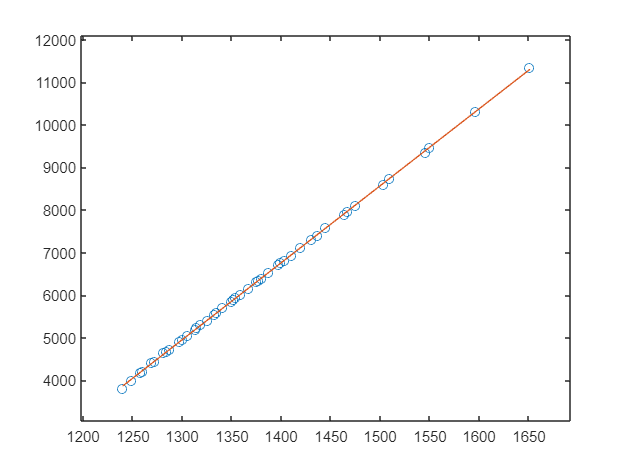

-- esfit ------------------------------------------------
Data size:                [10, 1]
Model function name:      @(p)linModel(Vc,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 9.10827e-02   edge 1.00000e-01   initial simplex
iteration   2: value 9.10827e-02   edge 1.00000e+01   contraction outside
iteration   3: value 9.10827e-02   edge 5.00000e+00   contraction inside
iteration   4: value 7.31305e-02   edge 2.50000e+00   contraction inside
iteration   5: value 6.60146e-04   edge 2.30625e+00   contraction inside
iteration   6: value 6.60146e-04   edge 2.50000e+00   reflection
iteration   7: value 6.60146e-04   edge 2.50000e+00   contraction inside
iteration   8: value 6.60146e-04   edge 2.50000e+00   contraction inside
iteration   9: value 6.60146e-04

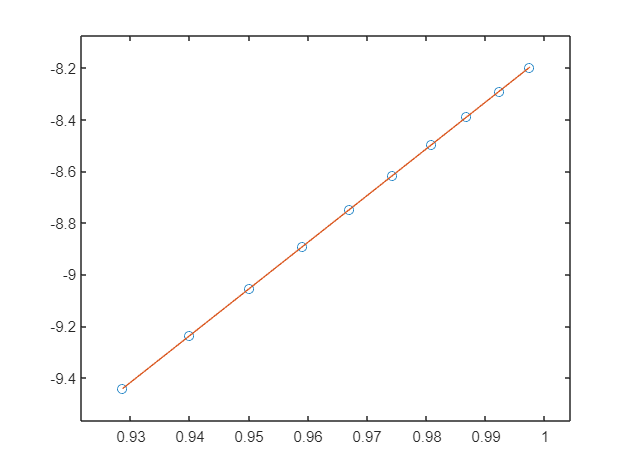

-- esfit ------------------------------------------------
Data size:                [28, 1]
Model function name:      @(p)linModel(Vc_,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 2.03448e-11   edge 1.00000e-01   initial simplex
iteration   2: value 2.02921e-11   edge 3.00000e+07   expansion
iteration   3: value 2.02921e-11   edge 2.00000e+07   reflection
iteration   4: value 2.02921e-11   edge 3.00000e+07   reflection
iteration   5: value 2.02322e-11   edge 2.50000e+07   expansion
iteration   6: value 2.02322e-11   edge 3.00000e+07   reflection
iteration   7: value 2.02322e-11   edge 3.00000e+07   reflection
iteration   8: value 1.99532e-11   edge 3.00000e+07   reflection
iteration   9: value 1.95686e-11   edge 3.00000e+07   reflection
iteration  10: va

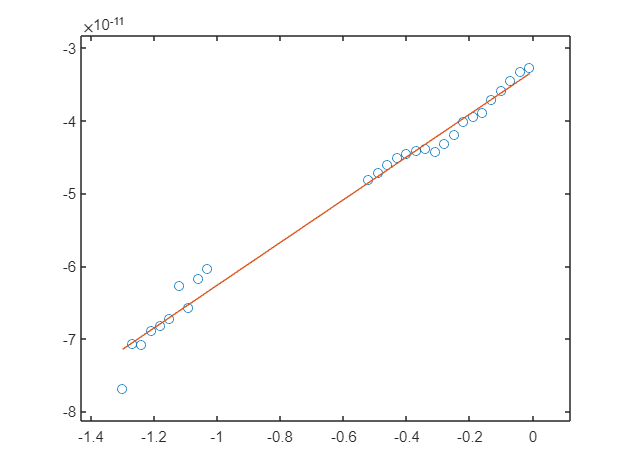

idxStrart = 79
==============   104



-- esfit ------------------------------------------------
Data size:                [36, 1]
Model function name:      @(p)linModel(x,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 9.38112e+01   edge 1.00000e-01   initial simplex
iteration   2: value 9.38112e+01   edge 2.00000e+03   contraction inside
iteration   3: value 9.38112e+01   edge 1.00000e+03   contraction inside
iteration   4: value 8.29467e+01   edge 5.00000e+02   contraction inside
iteration   5: value 2.05479e+01   edge 3.75000e+02   contraction inside
iteration   6: value 2.05479e+01   edge 5.00000e+02   reflection
iteration   7: value 2.05479e+01   edge 5.00000e+02   contraction inside
iteration   8: value 2.05479e+01   edge 5.00000e+02   contraction inside
iteration   9: value 2.05479e+01  

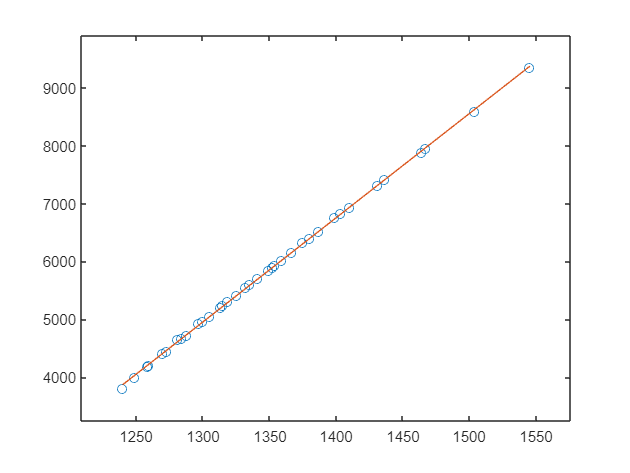

-- esfit ------------------------------------------------
Data size:                [9, 1]
Model function name:      @(p)linModel(Vc,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 7.64716e-02   edge 1.00000e-01   initial simplex
iteration   2: value 7.64716e-02   edge 1.00000e+01   contraction outside
iteration   3: value 7.64716e-02   edge 5.00000e+00   contraction inside
iteration   4: value 1.58185e-02   edge 3.75000e+00   contraction inside
iteration   5: value 1.58185e-02   edge 5.00000e+00   reflection
iteration   6: value 1.58185e-02   edge 5.00000e+00   contraction inside
iteration   7: value 7.06684e-03   edge 2.96875e+00   contraction inside
iteration   8: value 7.06684e-03   edge 2.96875e+00   contraction outside
iteration   9: value 3.92682e-03

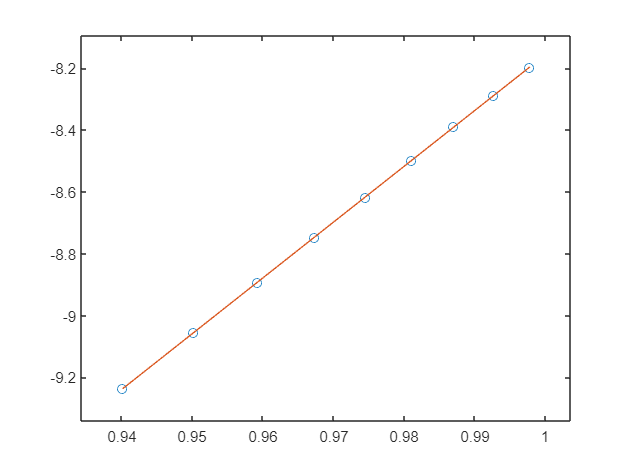

-- esfit ------------------------------------------------
Data size:                [28, 1]
Model function name:      @(p)linModel(Vc_,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 2.03779e-11   edge 1.00000e-01   initial simplex
iteration   2: value 2.03253e-11   edge 3.00000e+07   expansion
iteration   3: value 2.03253e-11   edge 2.00000e+07   reflection
iteration   4: value 2.03253e-11   edge 3.00000e+07   reflection
iteration   5: value 2.02652e-11   edge 2.50000e+07   expansion
iteration   6: value 2.02652e-11   edge 3.00000e+07   reflection
iteration   7: value 2.02652e-11   edge 3.00000e+07   reflection
iteration   8: value 1.99859e-11   edge 3.00000e+07   reflection
iteration   9: value 1.96009e-11   edge 3.00000e+07   reflection
iteration  10: va

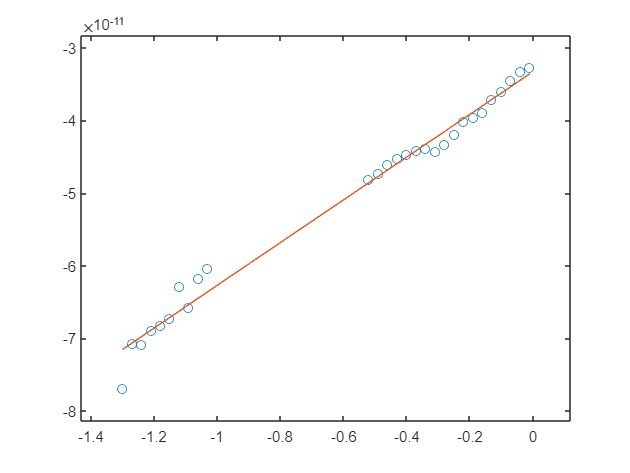

idxStrart = 80
==============   104



-- esfit ------------------------------------------------
Data size:                [28, 1]
Model function name:      @(p)linModel(x,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 8.32703e+01   edge 1.00000e-01   initial simplex
iteration   2: value 8.32703e+01   edge 2.00000e+03   contraction inside
iteration   3: value 8.32703e+01   edge 1.00000e+03   contraction inside
iteration   4: value 7.44864e+01   edge 5.00000e+02   contraction inside
iteration   5: value 2.02054e+01   edge 3.75000e+02   contraction inside
iteration   6: value 2.02054e+01   edge 5.00000e+02   reflection
iteration   7: value 2.02054e+01   edge 5.00000e+02   contraction inside
iteration   8: value 2.02054e+01   edge 5.00000e+02   contraction inside
iteration   9: value 2.02054e+01  

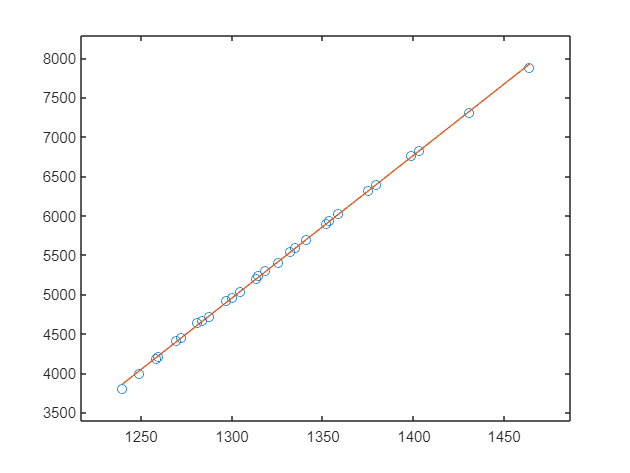

-- esfit ------------------------------------------------
Data size:                [8, 1]
Model function name:      @(p)linModel(Vc,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 6.59059e-02   edge 1.00000e-01   initial simplex
iteration   2: value 6.59059e-02   edge 1.00000e+01   contraction outside
iteration   3: value 6.59059e-02   edge 5.00000e+00   contraction inside
iteration   4: value 5.30692e-02   edge 2.50000e+00   contraction inside
iteration   5: value 9.67970e-04   edge 2.30625e+00   contraction inside
iteration   6: value 9.67970e-04   edge 2.50000e+00   reflection
iteration   7: value 9.67970e-04   edge 2.50000e+00   contraction inside
iteration   8: value 9.67970e-04   edge 2.50000e+00   contraction inside
iteration   9: value 9.67970e-04 

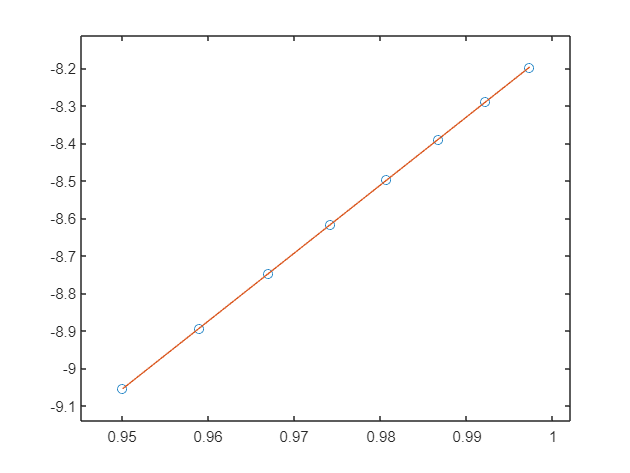

-- esfit ------------------------------------------------
Data size:                [28, 1]
Model function name:      @(p)linModel(Vc_,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 2.03444e-11   edge 1.00000e-01   initial simplex
iteration   2: value 2.02917e-11   edge 3.00000e+07   expansion
iteration   3: value 2.02917e-11   edge 2.00000e+07   reflection
iteration   4: value 2.02917e-11   edge 3.00000e+07   reflection
iteration   5: value 2.02318e-11   edge 2.50000e+07   expansion
iteration   6: value 2.02318e-11   edge 3.00000e+07   reflection
iteration   7: value 2.02318e-11   edge 3.00000e+07   reflection
iteration   8: value 1.99528e-11   edge 3.00000e+07   reflection
iteration   9: value 1.95682e-11   edge 3.00000e+07   reflection
iteration  10: va

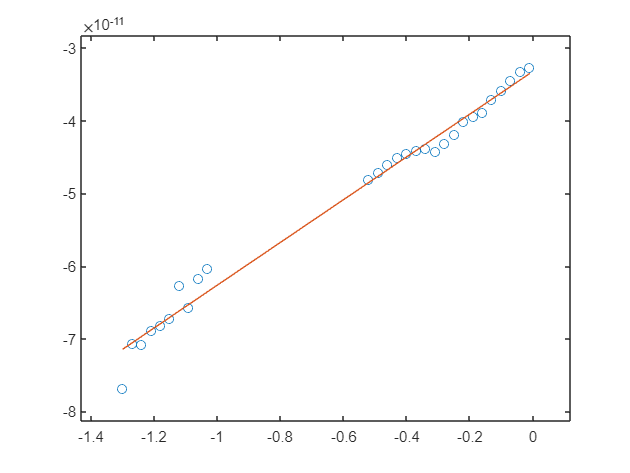

idxStrart = 81
==============   104



-- esfit ------------------------------------------------
Data size:                [21, 1]
Model function name:      @(p)linModel(x,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 6.84742e+01   edge 1.00000e-01   initial simplex
iteration   2: value 6.84742e+01   edge 2.00000e+03   contraction inside
iteration   3: value 6.84742e+01   edge 1.00000e+03   contraction inside
iteration   4: value 6.84742e+01   edge 5.00000e+02   contraction inside
iteration   5: value 4.67973e+01   edge 3.75000e+02   contraction inside
iteration   6: value 3.69466e+01   edge 2.81250e+02   contraction inside
iteration   7: value 2.02036e+01   edge 1.79688e+02   contraction inside
iteration   8: value 2.02036e+01   edge 1.79688e+02   reflection
iteration   9: value 1.97012e+01  

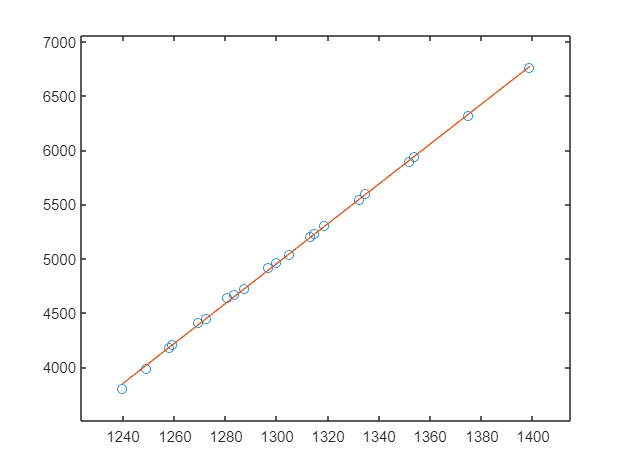

-- esfit ------------------------------------------------
Data size:                [7, 1]
Model function name:      @(p)linModel(Vc,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 5.75863e-02   edge 1.00000e-01   initial simplex
iteration   2: value 5.75863e-02   edge 1.00000e+01   contraction outside
iteration   3: value 5.75863e-02   edge 5.00000e+00   contraction inside
iteration   4: value 4.70948e-02   edge 2.50000e+00   contraction inside
iteration   5: value 4.32901e-03   edge 2.30625e+00   contraction inside
iteration   6: value 4.32901e-03   edge 2.50000e+00   reflection
iteration   7: value 4.32901e-03   edge 2.50000e+00   contraction inside
iteration   8: value 4.32901e-03   edge 2.50000e+00   contraction inside
iteration   9: value 4.32901e-03 

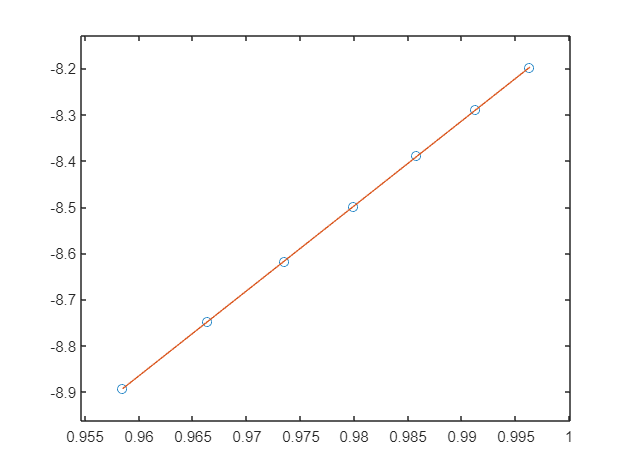

-- esfit ------------------------------------------------
Data size:                [28, 1]
Model function name:      @(p)linModel(Vc_,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 2.04204e-11   edge 1.00000e-01   initial simplex
iteration   2: value 2.03676e-11   edge 3.00000e+07   expansion
iteration   3: value 2.03676e-11   edge 2.00000e+07   reflection
iteration   4: value 2.03676e-11   edge 3.00000e+07   reflection
iteration   5: value 2.03075e-11   edge 2.50000e+07   expansion
iteration   6: value 2.03075e-11   edge 3.00000e+07   reflection
iteration   7: value 2.03075e-11   edge 3.00000e+07   reflection
iteration   8: value 2.00278e-11   edge 3.00000e+07   reflection
iteration   9: value 1.96422e-11   edge 3.00000e+07   reflection
iteration  10: va

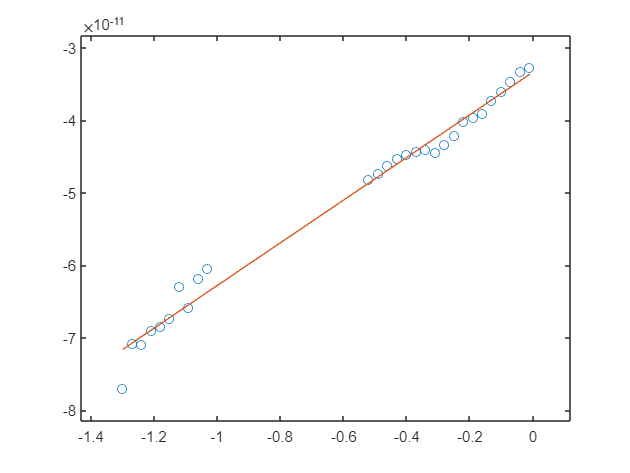

idxStrart = 82
==============   104



-- esfit ------------------------------------------------
Data size:                [15, 1]
Model function name:      @(p)linModel(x,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 5.19843e+01   edge 1.00000e-01   initial simplex
iteration   2: value 5.19843e+01   edge 2.00000e+03   contraction inside
iteration   3: value 5.19843e+01   edge 1.00000e+03   contraction inside
iteration   4: value 5.19843e+01   edge 5.00000e+02   contraction inside
iteration   5: value 2.99628e+01   edge 3.75000e+02   contraction outside
iteration   6: value 2.51371e+01   edge 3.43750e+02   contraction inside
iteration   7: value 2.51371e+01   edge 1.95312e+02   contraction outside
iteration   8: value 1.97681e+01   edge 1.30859e+02   contraction inside
iteration   9: value 1.9

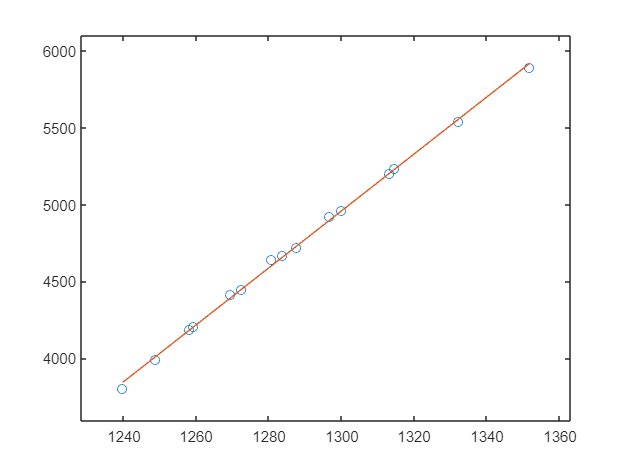

-- esfit ------------------------------------------------
Data size:                [6, 1]
Model function name:      @(p)linModel(Vc,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 4.82818e-02   edge 1.00000e-01   initial simplex
iteration   2: value 4.82818e-02   edge 1.00000e+01   contraction outside
iteration   3: value 4.82818e-02   edge 5.00000e+00   contraction inside
iteration   4: value 3.98148e-02   edge 2.50000e+00   contraction inside
iteration   5: value 5.24756e-03   edge 2.30625e+00   contraction inside
iteration   6: value 2.49236e-03   edge 2.50000e+00   reflection
iteration   7: value 2.49236e-03   edge 2.50000e+00   contraction inside
iteration   8: value 2.49236e-03   edge 2.50000e+00   contraction inside
iteration   9: value 2.49236e-03 

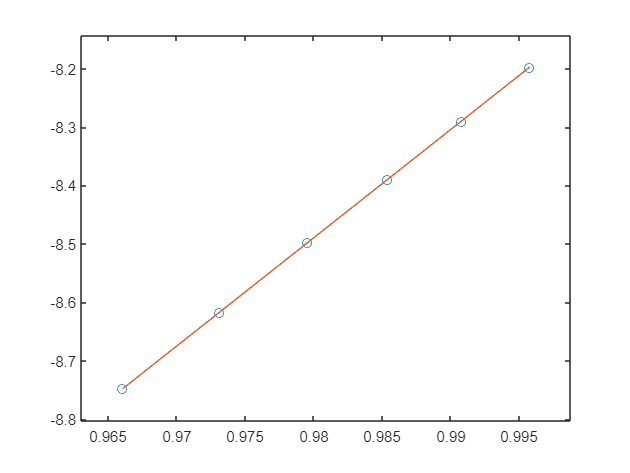

-- esfit ------------------------------------------------
Data size:                [28, 1]
Model function name:      @(p)linModel(Vc_,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 2.04314e-11   edge 1.00000e-01   initial simplex
iteration   2: value 2.03787e-11   edge 3.00000e+07   expansion
iteration   3: value 2.03787e-11   edge 2.00000e+07   reflection
iteration   4: value 2.03787e-11   edge 3.00000e+07   reflection
iteration   5: value 2.03185e-11   edge 2.50000e+07   expansion
iteration   6: value 2.03185e-11   edge 3.00000e+07   reflection
iteration   7: value 2.03185e-11   edge 3.00000e+07   reflection
iteration   8: value 2.00387e-11   edge 3.00000e+07   reflection
iteration   9: value 1.96530e-11   edge 3.00000e+07   reflection
iteration  10: va

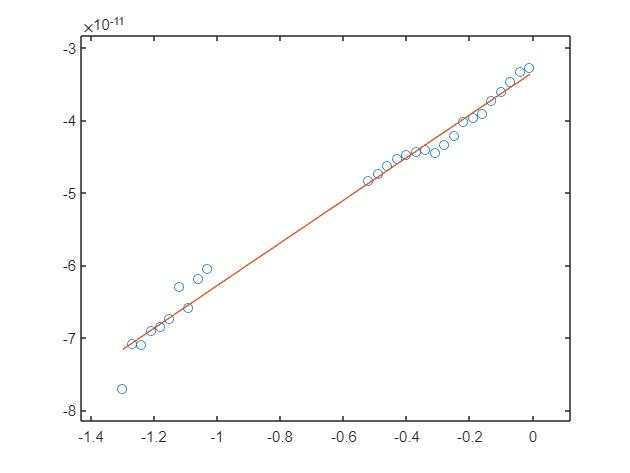

idxStrart = 83
==============   104



-- esfit ------------------------------------------------
Data size:                [10, 1]
Model function name:      @(p)linModel(x,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 2.94690e+01   edge 1.00000e-01   initial simplex
iteration   2: value 2.94690e+01   edge 2.00000e+03   contraction inside
iteration   3: value 2.94690e+01   edge 1.00000e+03   contraction inside
iteration   4: value 2.29324e+01   edge 5.00000e+02   contraction outside
iteration   5: value 2.29324e+01   edge 5.00000e+02   contraction inside
iteration   6: value 1.80769e+01   edge 3.12500e+02   contraction inside
iteration   7: value 1.80769e+01   edge 5.00000e+02   reflection
iteration   8: value 1.78864e+01   edge 2.81250e+02   contraction inside
iteration   9: value 1.78864e+01 

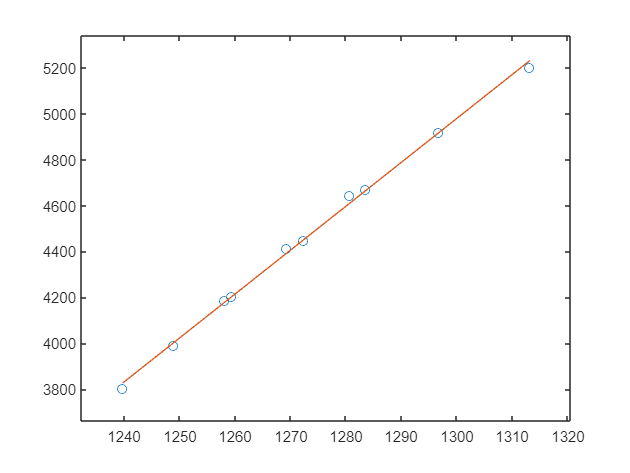

-- esfit ------------------------------------------------
Data size:                [5, 1]
Model function name:      @(p)linModel(Vc,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 3.44869e-02   edge 1.00000e-01   initial simplex
iteration   2: value 3.44869e-02   edge 1.00000e+01   contraction outside
iteration   3: value 3.44869e-02   edge 5.00000e+00   contraction inside
iteration   4: value 3.44869e-02   edge 3.60000e+00   contraction inside
iteration   5: value 1.37996e-02   edge 2.19375e+00   contraction outside
iteration   6: value 1.09827e-02   edge 1.71875e+00   contraction inside
iteration   7: value 1.09827e-02   edge 1.25156e+00   contraction outside
iteration   8: value 5.01730e-04   edge 7.81348e-01   contraction inside
iteration   9: value 5.

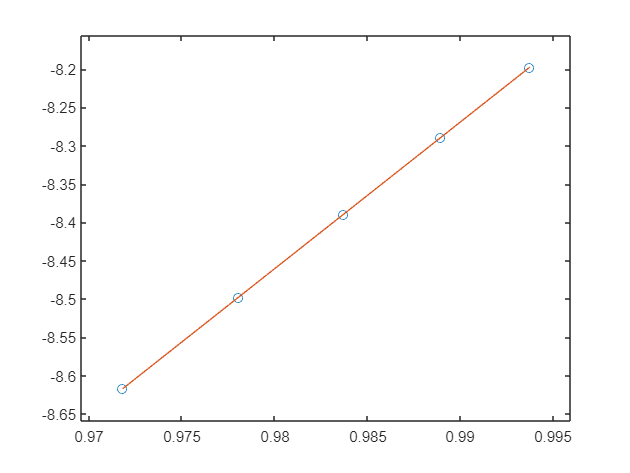

-- esfit ------------------------------------------------
Data size:                [28, 1]
Model function name:      @(p)linModel(Vc_,p)
Number of fit parameters: 2
Minimization algorithm:   Nelder-Mead simplex
Residuals computed from:  data as is
Autoscaling:              on
---------------------------------------------------------
Running optimization algorithm with 2 active parameters...
iteration   1: value 2.04279e-11   edge 1.00000e-01   initial simplex
iteration   2: value 2.03751e-11   edge 3.00000e+07   expansion
iteration   3: value 2.03751e-11   edge 2.00000e+07   reflection
iteration   4: value 2.03751e-11   edge 3.00000e+07   reflection
iteration   5: value 2.03149e-11   edge 2.50000e+07   expansion
iteration   6: value 2.03149e-11   edge 3.00000e+07   reflection
iteration   7: value 2.03149e-11   edge 3.00000e+07   reflection
iteration   8: value 2.00352e-11   edge 3.00000e+07   reflection
iteration   9: value 1.96495e-11   edge 3.00000e+07   reflection
iteration  10: va

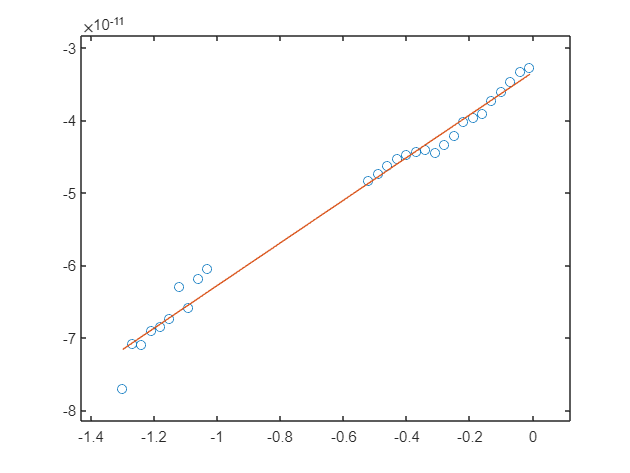

    alpha1_ = Fit1{ii}.scale*Fit1{ii}.pfit(1);
    Is1_ = exp(Fit1{ii}.scale*Fit2{ii}.pfit(2));
    Vc = V - I*Rs_;
    I1 = Is1_*(exp(alpha1_*Vc) - 1);

    I_ = ILow - I1(idxLow);
    V_ = VLow;
    Vc_ = Vc(idxLow);
    p0 = [1e-5, 1e-11]; % the second parameter here is due to the IV curve not going through (0,0)
    vary = [1e8, 1e5];
    FitOpt.x = V_;
    Fit3{ii} = esfit(I_,@(p) linModel(Vc_, p), p0, vary, FitOpt);

    xDummy = linspace(min(Vc_), max(Vc_), 1000);
    figure()
    plot(Vc_, I_, 'o')
    hold on
    plot(xDummy, Fit3{ii}.scale*Fit3{ii}.pfit(1)*xDummy + Fit3{ii}.scale*Fit3{ii}.pfit(2))
    xlim(setAxLim(Vc_, 0.1))
    ylim(setAxLim(I_, 0.1))
end

# Here there should be quadrature sum of the uncertainties!!!

[alpha1, alpha1Std, alpha11, alpha11Std, n1, n1Std, ...
    Rs, RsStd, Is1, Is1Std, Rsh, RshStd] = deal(zeros(nStart, 1));
for ii = 1:nStart
    Fit1_ = Fit1{ii};
    S = Fit1_.scale;
    alpha1(ii) = S*Fit1_.pfit(1);
    alpha1Std(ii) = S*Fit1_.pstd(1);
    n1(ii) = 1/(alpha1(ii) * V_T);


$${d\;n}_1 =d\;\left(\frac{1}{\alpha_1 V_T }\right)=$$
 
$$\frac{1}{{\alpha_1 }^2 V_T }d\alpha +\frac{1}{\alpha_1 V_T^2 }{\textrm{dV}}_T =n_1 \left(\frac{d\;\alpha \;}{\alpha \;}+\frac{d\;V_T }{V_T }\right)$$
 

    n1Std(ii) = n1(ii)*(alpha1Std(ii)/alpha1(ii) + V_TStd/V_T);
    Rs(ii) = -S*Fit1_.pfit(2)/alpha1(ii);


$$d\;R_S =d\;\left(\frac{p_2 }{\alpha \;}\right)=\frac{d\;p_{2\;} }{\alpha \;}+\frac{p_2 }{\alpha^2 }d\alpha =R_S \left(\frac{{d\;p}_2 }{p_2 }+\frac{d\alpha }{\alpha \;}\right)$$


    RsStd(ii) = Rs(ii)*(Fit1_.pstd(2)/Fit1_.pfit(2) + alpha1Std(ii)/alpha1(ii));

    Fit2_ = Fit2{ii};
    S = Fit2_.scale;
    alpha11(ii) = S*Fit2_.pfit(1);    % Another value of alpha
    alpha11Std(ii) = S*Fit2_.pstd(1);
    Is1(ii) = exp(S*Fit2_.pfit(2));


$$d\;I_S \;=d\;\left(\exp \left(p_2 \right)\right)=\exp \left(p_2 \right)*d\;p_2 =I_S *{d\;p}_2$$


    Is1Std(ii) = Is1(ii)*S*Fit2_.pstd(2);

    Fit3_ = Fit3{ii};
    S = Fit3_.scale;
    Rsh(ii) = 1/(S*Fit3_.pfit(1));
    RshStd(ii) = Rsh(ii)*Fit3_.pstd(1)/Fit3_.pfit(1);
end
bestFit = struct('IDX_START_INITIAL', IDX_START_IN, ...
    'IDX_START_FINAL', IDX_START_FIN, ...
    'alpha1', alpha1, ...
    'alpha1Std', alpha1Std, ...
    'n1', n1, ...
    'n1Std', n1Std, ...
    'alpha11', alpha11, ...
    'alpha11Std', alpha11Std, ...
    'Rs', Rs, ...
    'RsStd', RsStd, ...
    'Is1', Is1, ...
    'Is1Std', Is1Std, ...
    'Rsh', Rsh, ...
    'RshStd', RshStd);
% To save also the RMSD values compile also next section
save('D:\Profile\qse\Files\_EDMRoC pinSC\IV curve\SuSi\a-Si_pin_Solar_Cell_AM1p5G.mat', "V", "I", "bestFit", "Fit1", "Fit2", "Fit3")

# Analysis of fit results

index 9 (idxStart = 75) gives the best rmsd

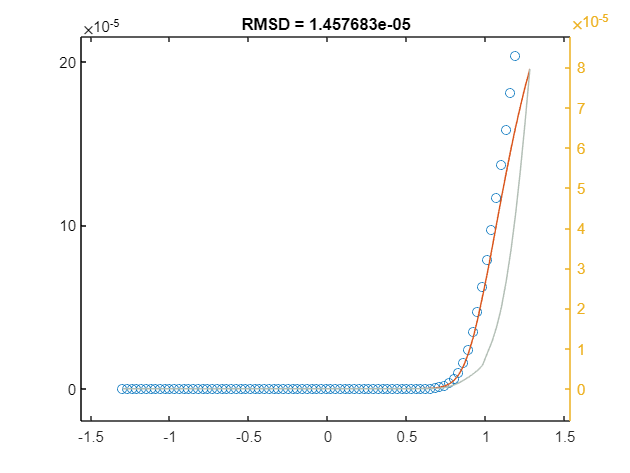

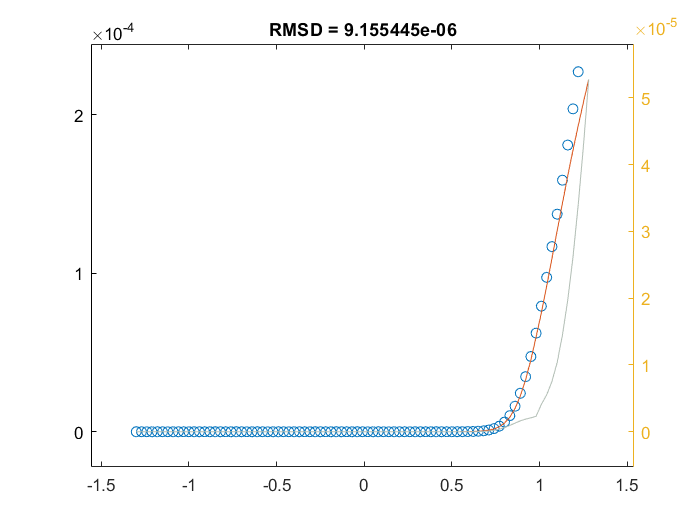

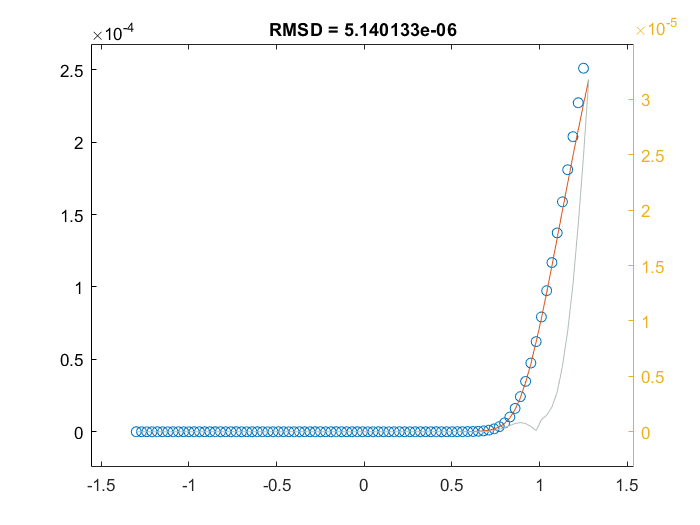

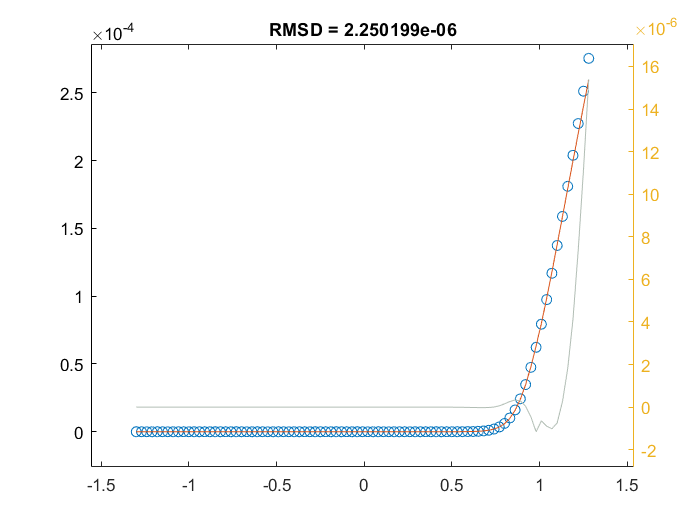

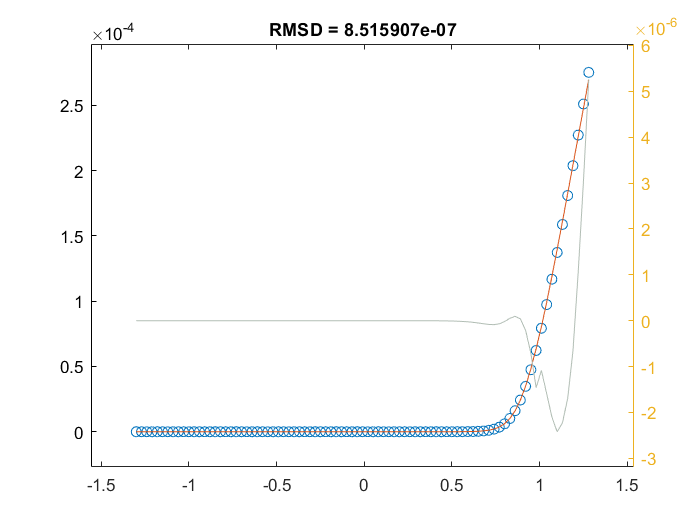

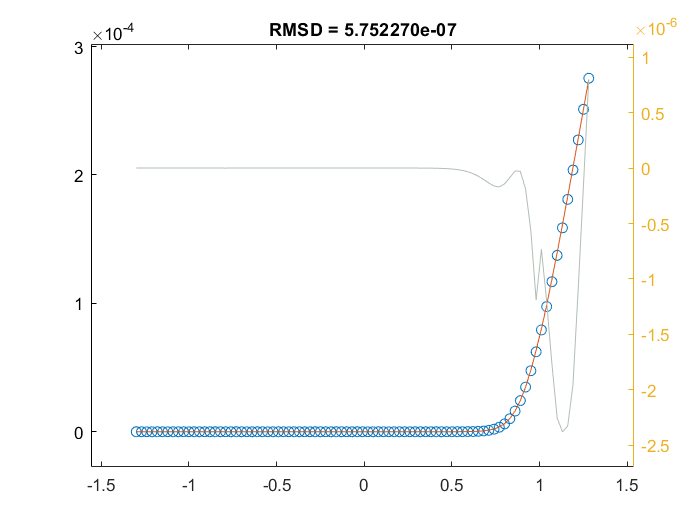

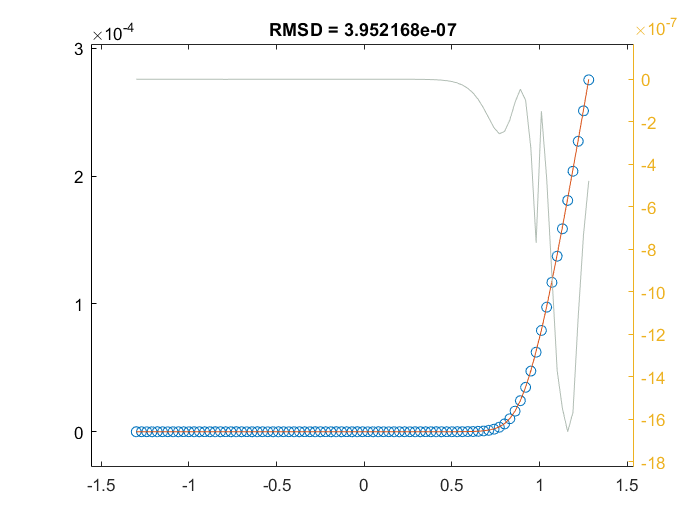

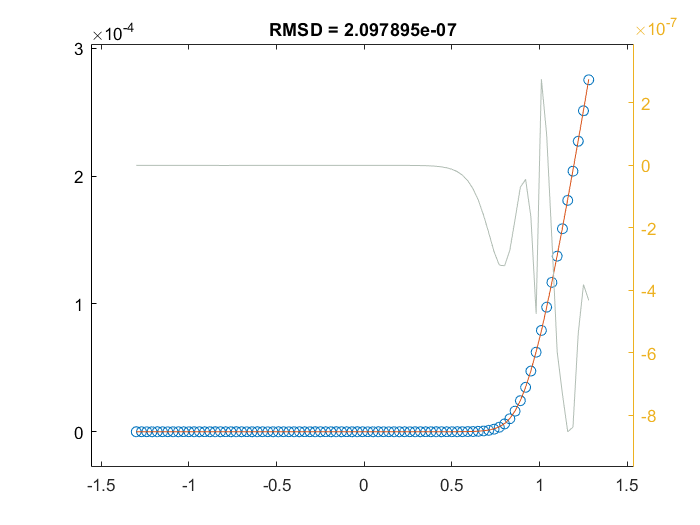

addpath(genpath('D:\Profile\qse\Files\soft\software\Matlab'));
load('D:\Profile\qse\Files\_EDMRoC pinSC\IV curve\SuSi\a-Si_pin_Solar_Cell_AM1p5G.mat');
load('GrayColorResiduals.mat');
Rmsd = ones(numel(Fit1), 1);
for ii = 1:numel(Fit1)
    Is_ = bestFit.Is1(ii);
    Rs_ = bestFit.Rs(ii);
    Rsh_ = bestFit.Rsh(ii);
    alpha_ = bestFit.alpha1(ii);
    Ifit_ = onediodemodel(V, I, [Is_, Rs_, Rsh_, alpha_]);
    Fit1_ = Fit1{ii}; Fit2_ = Fit2{ii}; Fit3_ = Fit3{ii};
    Rmsd(ii) = rms(I-Ifit_);
    figure()
    tL = tiledlayout('flow');
    nexttile
    plot(V, I, 'o')
    hold on
    plot(V, Ifit_)
    xlim(setAxLim(V, 0.1))
    ylim(setAxLim(Ifit_, 0.1))
    yyaxis right
    plot(V, I - Ifit_, 'Color', GrayColorResiduals)
    ylim(setAxLim(I - Ifit_, 0.1))
    title(sprintf('RMSD = %d', Rmsd(ii)))
end

bestFit.Rmsd = Rmsd;
% save('D:\Profile\qse\Files\_EDMRoC pinSC\IV curve\SuSi\a-Si_pin_Solar_Cell_AM1p5G.mat', "V", "I", "bestFit", "Fit1", "Fit2", "Fit3")

function [Ifit, C] = ILowVoltage(I, Vc, alpha2)
    I_ = exp(alpha2*Vc) - 1;
    X = [I_ Vc];
    C = X \ I;      % C(1) = Is2, C(2) = 1/Rsh
    Ifit = X * C;
end
function Ifit = onediodemodel(V, I, p)
    % p = [I0, Rs, Rsh, alpha]
    Idiode = p(1)*(exp(p(4)*(V - I*p(2))) - 1);
    Ish = (V - I*p(2))/p(3);
    Ifit = Idiode + Ish;
end
function Ifit = twodiodemodel(V, I, p)
    % p = [I01, Rs, Rsh, alpha1, I02, alpha2]
    Idiode1 = p(1)*(exp(p(4)*(V - I*p(2))) - 1);
    Idiode2 = p(5)*(exp(p(6)*(V - I*p(2))) - 1);
    Ish = (V - I*p(2))/p(3);
    Ifit = Idiode1 + Idiode2 + Ish;
end